# DataAnalysisTemplate.mls

Simulates calibration and characterization of an instrument to extract a mass measurement and its error. Illustrates: - MATLAB plotting functions including histogram, plot, scatter, errorbar, histfit, fitdist, and labels, titls, legends, and annotations. - filtering and fast fourier transform fft - curve fitting methods polyfit(linear) and fitnlm(nonlinear). - process of data analysis using data, modeling, and physical intuition to extract optimal measurement.

## Introduction

In an experiment, you often have at your disposal an instrument and a procedure, represented here by a function call y=FakeDataGameGeneratorFunction(mass,t), which returns n sequential measurements y=[y_1...y_n] of a quantitiy y at times [t_1 ... t_n]. You must calibrate and characterize the instrument in order to measure an unknown quantity. 

This program illustrates the sorts of steps you might take in weighing an object of mass m between 0 and 10 kg using a simple vertical compression spring with one end fixed, the mass attached to a platform at the other end. The downwards force on the mass is the sum of a force of (local) gravity $F_g=mg$ and a spring force $F_s = -kx$ where k is a characteristic of the particular spring, called the spring constant, and $x$ is the displacement from the equilibrium position for $m=0$. We must have in equilibrium a balance of forces, $F_g+F_s=0$, so $x_{equilibrium} = m(g/k)$ is proportional to mass. Measurements of $x_{equilibrium}$ translate to measurements of weight (mg) or inertial mass m, given g and k.

The simulation of the use of such a scale illustrates issues in designing and in using a precision instrument based on these simple ideas. The issues encountered are general. Use these methods of analysis in all of your labs, both the ideas and methods. 

The MATLAB code is sophisticated and intended to be illustrative. Since you are just starting to learn MATLAB, it may appear daunting. Read the comments (and emulate the practice in your own codes) and look up the MATLAB documentation on each function call you encounter to understand what is happening. You need not understand nevermind remember everything.

The program and the attached functions are a Live Script that you can execute, change, and re-execute section by section or in its entirety, within the MATLAB environment. You can run little tests in the command window to test your understanding.

An attached function simulates a platform supported or suspended by a linear spring. The equilibrium position of the platform is linearly related to the mass placed on the platform and which is transduced to provide a mass measurement as just described. A traditional bathroom scale uses a lever to convert a small displacement of the platform into a needle deflection mechanically. Our virtual scale provides digital results with a fixed precision like many modern bathroom scales. The simulation includes a variety of dynamical and illustrative instrumental effects.

Feel free to study the simulation AFTER following along in the game of taking measurements and trying to understand the results. You might try the actual experiment with a bathroom scale at home. Weigh yourself and ask yourself how accurate the value is and how to find out. My tests show bathroom scales even of the same brand produce significantly different results, the variation being as much as several pounds weight.

Ancillary functions for plotting are also attached. Caution: This program clears all workspace variables and plots so save any work in progress before executing.

## Preliminaries

Clear away the workspace variables

clearvars;

Delete any figures. 

delete(findall(0,'Type','figure'))

Reset seed for random number generator for reproducibility. The simulation uses normrnd to generate normally distributed random numbers. These are generated algorithmically from a seed and are pseudorandom. Starting with the same seed gives exactly the same sequence. Type `>>randtool` in the command window to play with and export samples from various distributions. These are available through a more general generator `rand`.

rng('default')

## The first step is to power the instrument and take some mass measurements.

Let's imagine we take some measurements with zero mass. Suppose it takes one sec to make a measurement. Take a bunch and record the times of the measurements for reasons about to become clear. We will use high statistics sampling assuming a digital readout. You can reduce the number of samples later to get a sense of the impact of the low statistics you might obtain by eyeball readings and manual recording of an actual mass on a physical metal coil spring. Assume the instrument produces mass in SI units (kg).

Set number of measurements. Yes, we are greedy here...

n=200;

Create a row vector of times t= [1 2 ... n] seconds.

t=[1:n];

Set the true value of the mass placed on the platform.

mass=0;

Call the procedure to return a (row) vector of measurement results and assign it the name y.

y=FakeDataGameGeneratorFunction(mass,t);

Done. That was easy, eh? In coding, for clarity, define quantities as variables before using them. A call here like `y=FakeDataGameGeneratorFunction(0,[ 1 2 3]) `would require the reader know in advance what each of the arguments of the function call were. Naming them before using them makes meaning evident.

BTW, y is a vector as you can check in the MATLAB workspace pane  after running this section. Do check. What gets returned is not obvious without studying the function or some documentation or trying it.  The workspace tells you the size (200) and kind of object and allows you to drill in to it. Type the command `>>y(1:10)` ion the command window after this section has run to print just the first 10 entries.

## At every step, study the results and understand them by making plots.

Plot results versus time. Always label axes clearly giving the meaning of the variable and the units for both x and y axes, and provide an explanatory title.

Create a new figure window.

figure

Make a plot in the current figure with axis labels and top title.

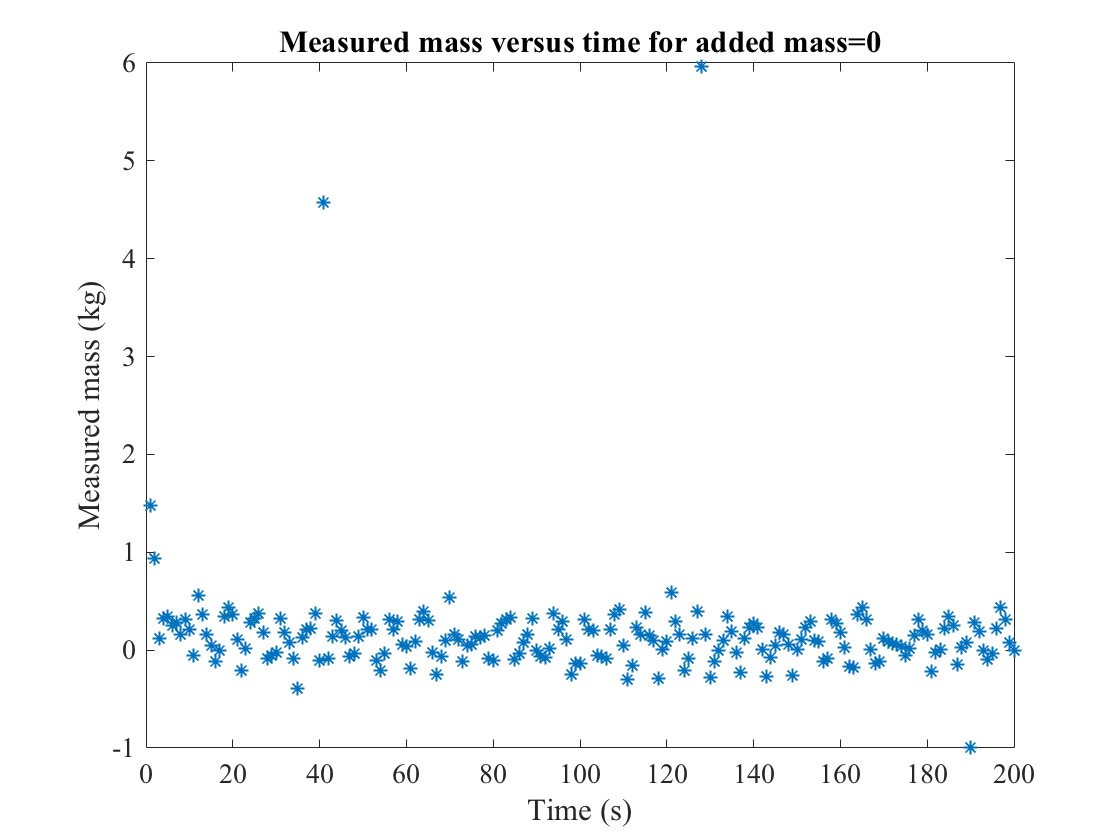

plot(t,y,'*');xlabel('Time (s)');ylabel('Measured mass (kg)');
title('Measured mass versus time for added mass=0');

The command plot, xlabel, ylabel, title have many options. Take a quick look at their documentation. A plot is a set of points. The asterix is a choice of point symbol. Without that symbol, the default is to NOT draw points and to draw straight lines between points. Replacing * with *- will draw points and connecting lines. Connecting lines alone are generally inapppropiate for data. It can be difficult to tell where the data points are and then lines suggest a correlation which may or may not exist. Connecting is appropriate if you are illustrating a function and the lines stand for intermediate points. 

Note you could be more specific and give the window a name "fig1" via

the statement `fig1=figure;` and then select it as the current figure via

the command `figure(fig1)` before the plot command so you could refer to

and add to the figure later after creating some other current default figure.

MATLAB chooses the boundaries and tick marks of a plot automatically for you but you can change them - look at the help for the plot command. The plot  is live in MATLAB so you can zoom and pan around. Try it!

## What can we observe here....

Notice that the results jump around a value near zero, and there are some odd values (outliers). These are important observations. Maybe this reminds you of your experience with a bathroom scale reading "jumping around?"

## Histogram the results

A histogram of a vector y ignores any ordering and counts the number of values in each of a set of small contiguous ranges (bins). The counts are displayed as a bar chart ordered by value, with bar width proportional to bin width. In our case, histogramming y is like projecting the mass vs time plot onto a set of bins arrayed on the y-axis, each point in any bin range piling atop like value points, the pile height giving the count. The bins are usually chosen to have the same width. But if we choose variable bin widths, it gets more subtle.

MATLAB's histogram command (the command hist is deprecated) makes such a plot in an instant, automatically selecting the bin centers and equal bin widths and the range to best represent the distribution.

Make a new figure which becomes the default figure. Else "histogram" will overwrite the current figure created previously by "plot". If a figure is missing for you, you probably overwrote it!

figure
histogram(y)
xlabel('Measured mass (kg)');ylabel('Counts (events)')

Note, ending a command with ; supresses any printout AND allows adding another on the same line. ylabel prints nothing so no ; is needed.

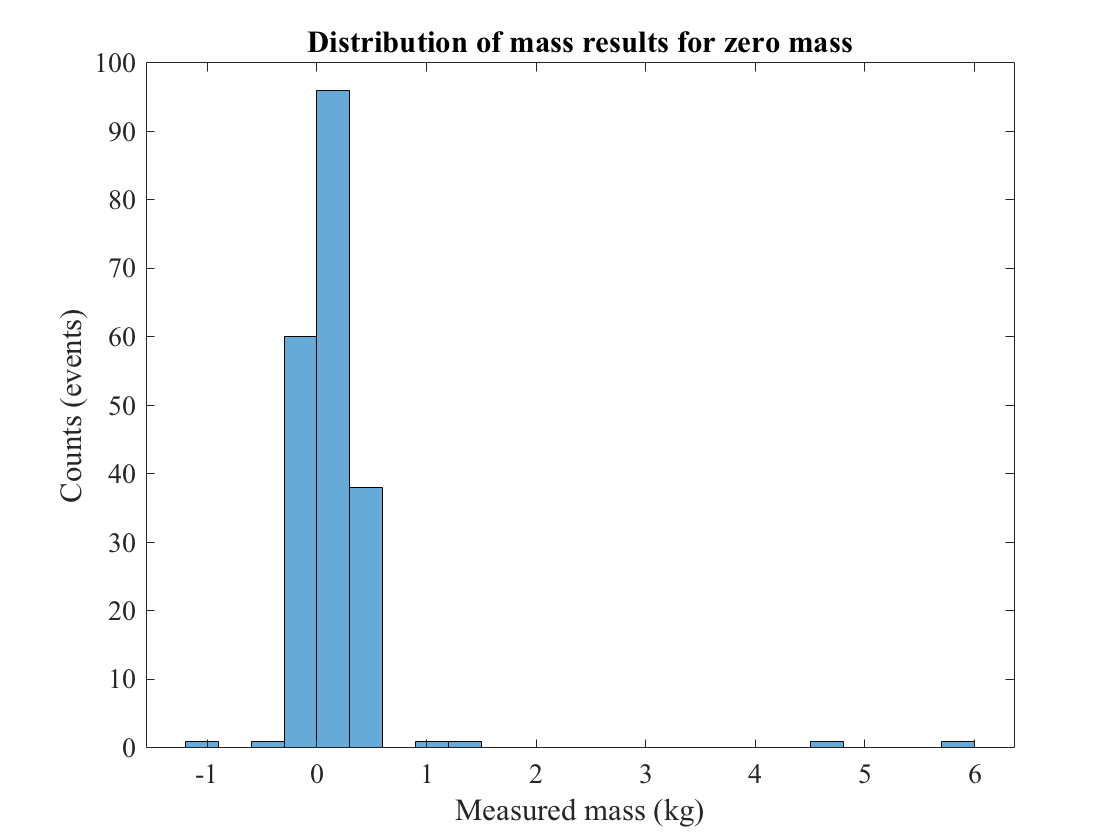

title('Distribution of mass results for zero mass')

The values corresponding to the tops of the bars are the number of counts or events in each bin so have no units. The label defines the meaning of the numerical value. Do NOT label the y-axis as "Frequency," a word defined to mean rate with dimensions of inverse time. There was no reference to any time values in the construction of the histogram and the data was treated as categorical not as a sequence. If you dividedthe counts by binwidth (with units of x) and by a time interval and plotted the values versus bin center values, you could sensibly label the y-axis values "Measured mass frequency density ( $kg^{-1} s^{-1}$)". Do not label counts as "Relative frequency" which has no units as it begs the question "Relative to what?" 

Try in the command window the following to see the difference:

>>%Let MATLAB pick equal bin size

>>y=[1:10];figure; histogram(y);ylabel('Counts')

>>% I will pick my own bin lower edges

>>edges=[1 3 4 5 6 7 8 9];figure; histogram(y,edges);ylabel('Counts')

The lowest bin in the 2nd case is twice as wide and twice as tall. The highest bin collected the "10" and is twice as tall and the same width. Both bins have 2 counts.

Look up the histogram command. One of many options ('Normalization','pdf') is to replace the counts by the relative probability of occurance by dividing each count by the bin size and by the total number of events. Dividing by the bin size gives the y-axis values units of counts/unit, where unit is the units of the x-axis, e.g. (counts/ kg). The values depend upon the binwidths which might not be uniform. Dividing by the total number of events N gives the y-axis units of (1/unit), e.g. (1/kg). This is appropriately called "Probability density (1/kg)". Note, there is no reference to time here. Shuffling the events will not change the histogram. Dividing by N ('Normalization','Probability') gives a dimensionless quantity. If the binwidths are different, the probability and probability density ratios do not have the same value across the histogram.

Let's illustrate:

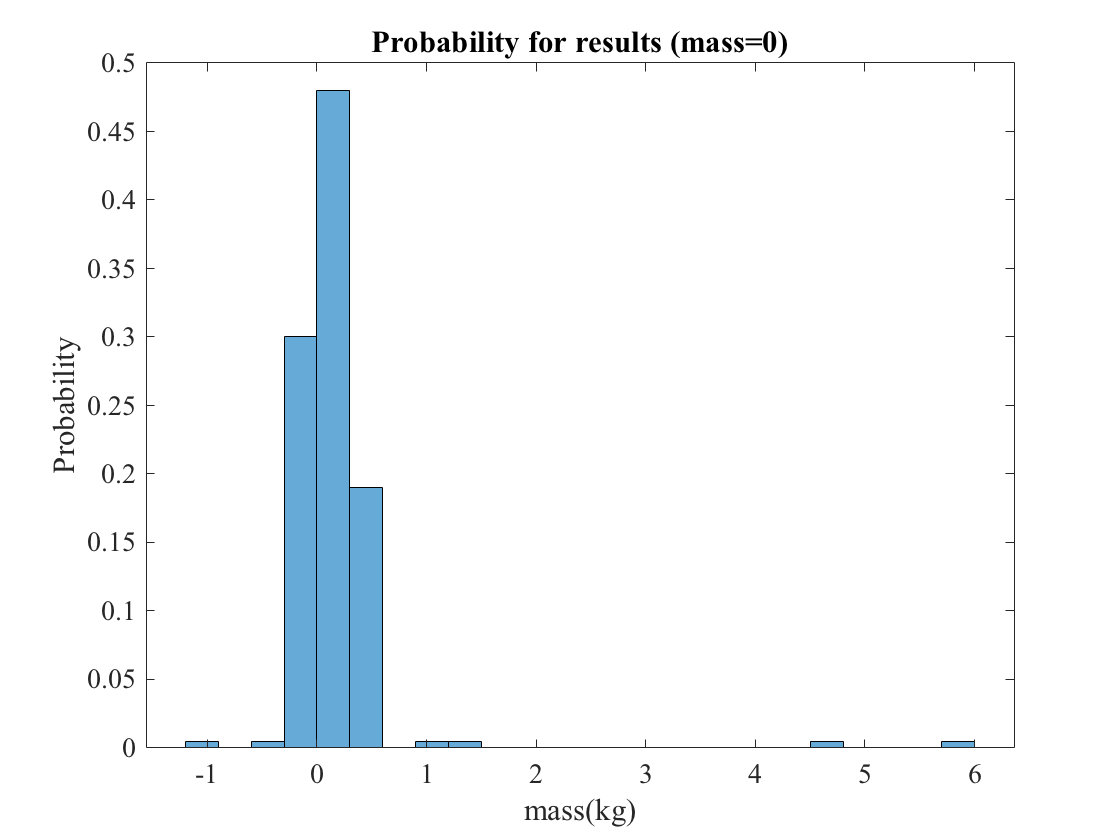

figure
histogram(y,'Normalization','Probability')
xlabel('mass(kg)');ylabel('Probability')
title('Probability for results (mass=0)')

We can also histogram and fit to a distribution function 'dist' such as a normal or beta function in one go using `histfit(y,'dist')`, and dump the fitted parameter values with a call to `fitdist`. Let's fit over a restricted range -0.5<y<+0.5 so the tail doesn't pull the fit.  We will try a normal/gaussian distribution.

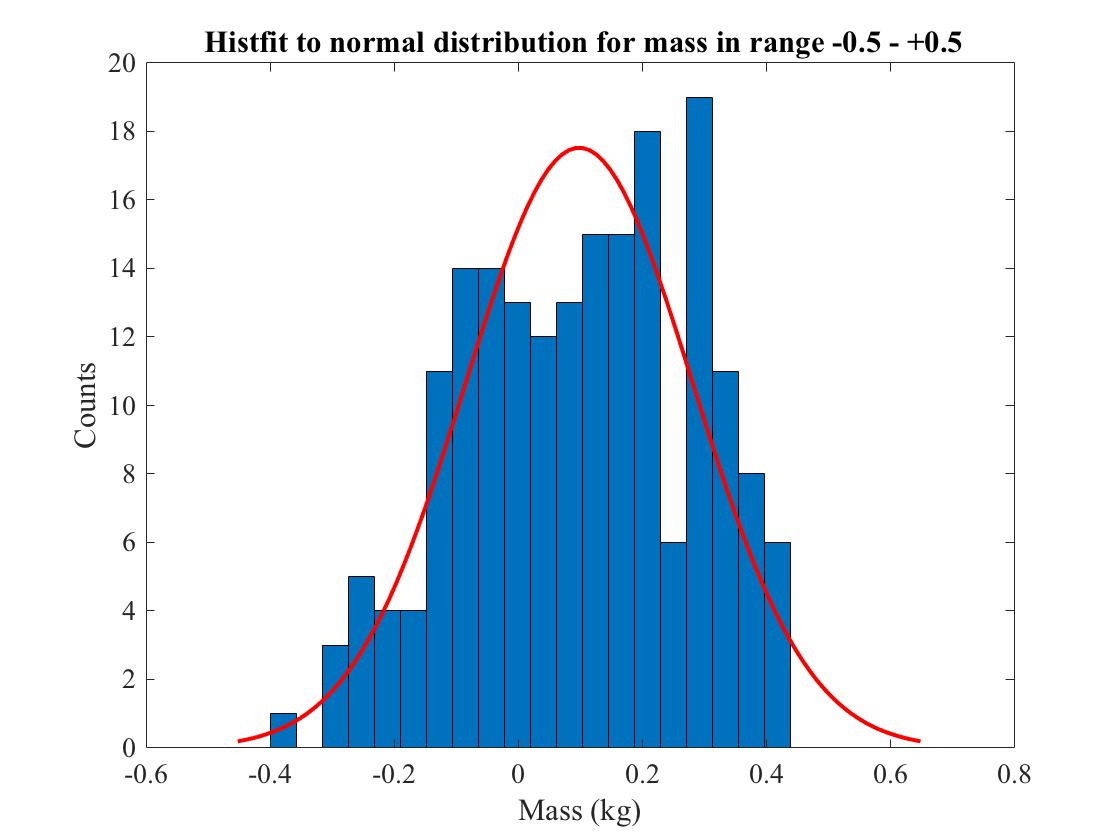

figure
nbins=20;% no. of bins in the histogram to be made
histfit(y(abs(y)<0.5),nbins,'normal');
xlabel('Mass (kg)');ylabel('Counts');
title(' Histfit to normal distribution for mass in range -0.5 - +0.5');

## Making selections

To understand the powerful selection construct `y(abs(y)<0.5` just used, try the following: 

>> y=[1:5]

>> y<3

>> y(y<3)

The expression "y<3" is a vector of logicals (1 for true and 0 for false). The expression `y(y<3)` is a vector with the original elements y(i) not satisfying y(i)<3 ejected. Through such expressions, MATLAB makes it easy to effectively code a procedure to loop over entries in the original vector, test if the entry satisfies the condition, and if so add it to a new vector. This compact language takes some getting used to. Read it in words as "Give me the y's such that y is less than three."

## Fitdist fit parameters

Histfit uses `fitdist`. We can call `fitdist`  directly ourselves too. It wants

a column vector so we use `' `to transpose the input row vector.

pd=fitdist(y(abs(y)<2)','Normal')

pd =   NormalDistribution

  Normal distribution
       mu = 0.111341   [0.0784309, 0.144252]
    sigma = 0.234825   [0.213749, 0.260546]


`Fitdist` fits the array in its first argument to a distribution type specified by a name that must match a distribution function it knows about. Because there is no ; at the end of the preceding line, MATLAB prints the hist object we gave the name `pd` which contains results and other information. Extract and save the fit parameters (mean and std of fitted normal distribution)  thusly:

histfitmean=pd.mu,histfitstd=pd.sigma

histfitmean =       0.11134

histfitstd =       0.23482

The datastructure.propertyofstructure syntax invokes a specific procedure to extract the needed value from the data structure. In our case, the structure is a hist object and the .mu means give me back the thing you call mu, the mean, please.

## Observe and make notes of observations as you proceed.

Note that our distribution is not well modelled by a normal distribution shape. It can have two peaks even, depending on the sample. That is a significant observation, and connected to oscillation of our signal.

## Explore

It is a good idea to explore a bit the instrument. Our simulated instrument can provide data over very fine time increments and long times. Try, say, 200 seconds every 1/10 s.

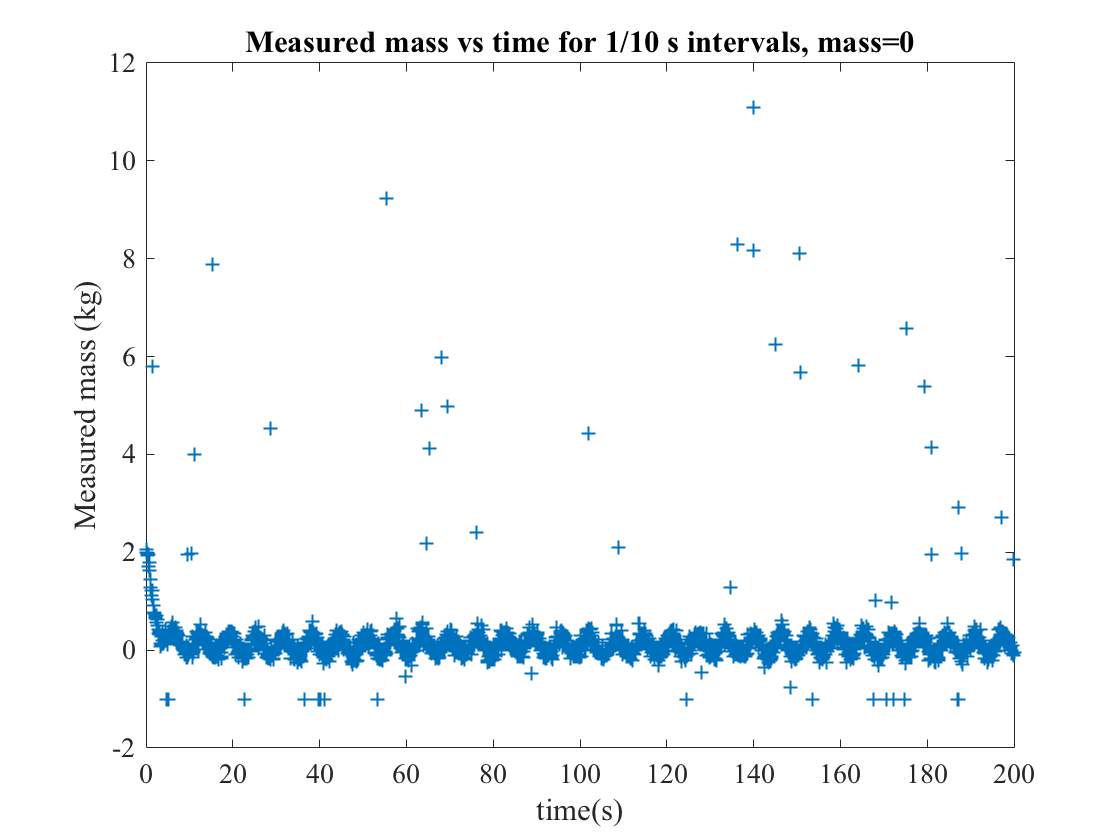

tmax=200;
t=[1:tmax*10]/10;
y=FakeDataGameGeneratorFunction(mass,t);
% Make a new figure or MATLAB will overwrite the last one. 
% Use + not * as a lighter weight symbol.
figure;
plot(t,y,'+'); xlabel('time(s)');ylabel('Measured mass (kg)')
title('Measured mass vs time for 1/10 s intervals, mass=0')

## Look at each plot carefully and make hypotheses about what you see!

With more and better data, a definite time structure appears in the values that was obscure with less data. This wiggling is giving rise to much of the variation in the results, and to the non-normal distribution of results. There are some spurious events at random times. We also clearly see a transient phenomenon after turn-on at time 0, roughly an exponential decay gone by 20 s or so. Spurious events are hitting the lower limit (-1) of the readout dynamic range. Those must be sourced internally to the instrument before the readout, unless some subsequent digital processing step was so truncating them at the same value. Or there could be two spurious event sources, one of which gives the negative values. 

These hypotheses concerning the salt and pepper noise points could be investigated, and should be. But we will use a filter to remove most of them from our data below. The investigation of the spurious events should be put on a "to-do" list. In reality, you should immediately try to eliminate spurious noise and oscillation before proceeding with further data collection and analysis. But if e.g spurious events are due to e.g. some electrostatic sparking inside a powered device, maybe you don't have the expertise to safely fix the problem.

## Lag plots

A lag plot is a scatter plot of all members y_n of a sequence versus y_(n-m) where m is a fixed number. If the y values are uncorrelated in time, the scatterplot will show no correlation. If the times are a fixed interval dt apart, and $y_n=f(t_n)$ is derived from sampling a function $f(t)$, then $y_n-y_(n-1)=f(t_n)-f(t_(n-1)) ~ f'(t_n) dt$ with $f'=df/dt$ so $(y_n, y_(n-1))= (y_n, y_(n-1)+(y_n-y_(n-1))~(y(t),y(t)+y'(t)dt)$. The lag plot pairs are a time sampling of the phase space, $(f(t),f'(t))$. For example, sampling $y=\sin(2\pi ft)$ and $y'=2\pi f\cos(2\pi f t)$ and plotting $y' $vs $y$ will give points on an ellipse.

We can use the MATLAB function `circshift` to circulate the elements of a vector and make a lag plot. The following compares a lag plot.

Make a sine function, with and without blurring by normally distributed random noise, to the data. The data ellipse is blurred by random noise.

f=0.15; % frequency in Hz
x=2*pi*f*[0:1000]/10;% vector of times with 1001 elements
z=histfitmean+0.2*sin(x)/2; % a sinusoidal signal vector to illustrate
% MATLAB applied the right hand side to each element of x giving a vector 

Make a new figure and plot `z` vs a lagged` z using scatter.`

figure
scatter(circshift(z,-1),z);
hold on

Blur the sine with random noise distributed like found in histogram. We use the function normrnd which generates random values distributed normally with provided mean and standard deviation. We provide values from our previous results and say we want a vector out. So we get a vector of 1001 random numbers and add this to our signal vector.

z=z+normrnd(histfitmean,histfitstd,[1,length(x)]);

Now we make a scatter plot of a values versus lagged values using  circshift(z,-1) to circulate the elements of z by one position again. We use

scatter(circshift(z,-1),z);

Superpose our data, selecting events with measurements close to zero to compare

w=y(abs(y)<1);scatter(circshift(w,-1),w,'+');
title('Lag plot: measurements compared to sin wave');

The legend command illustrated here provides a legend of quantities in the order in which they were added to the figure.

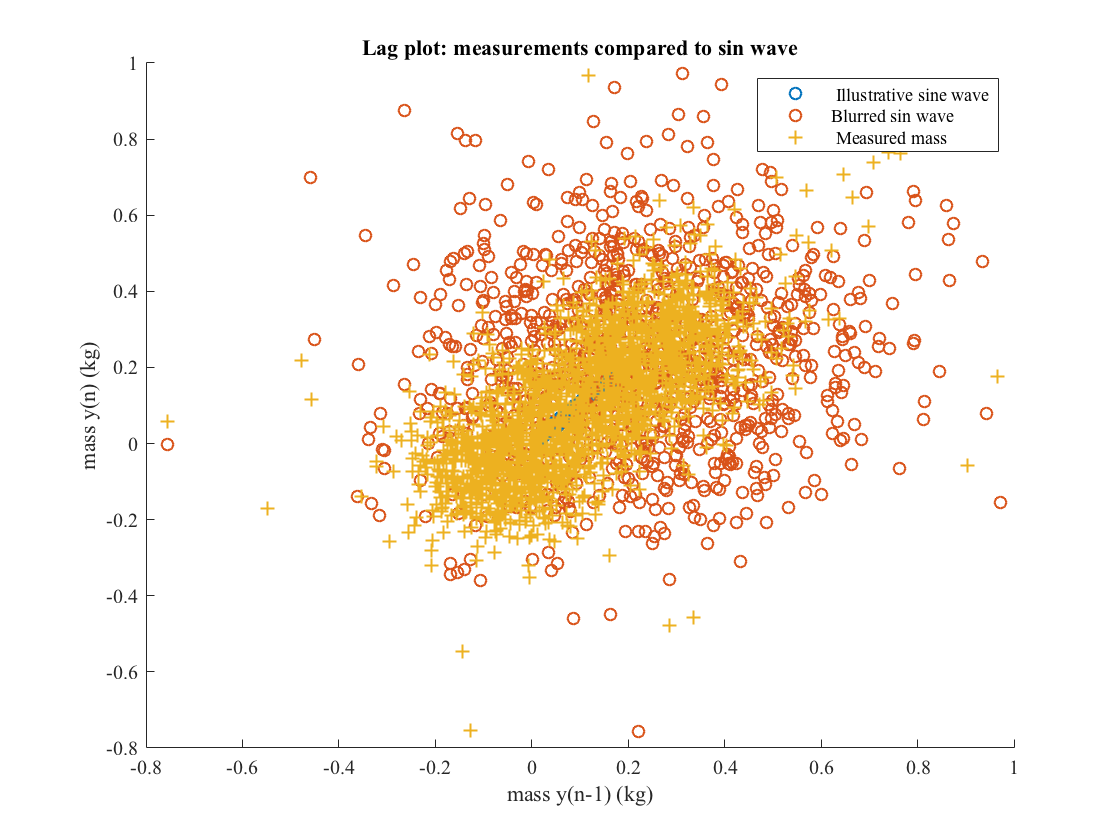

legend(' Illustrative sine wave','Blurred sin wave',' Measured mass');
xlabel('mass y(n-1) (kg)');ylabel('mass y(n) (kg)');hold off

You need to zoom in to see the unblurred form.

## Fast fourier transform

The lag plot and the generalization to autocorrelation (MATLAB `autocorr)` are generic tests for correlation and in our case weakly indicate correlation. Your eye can pick out an oscillation in the time sequence plot better than in the lag plot because it is looking for longer term correlation. A more incisive test for oscillation is the discrete fourier transform (DFT) $z(k)=\sum_{m=0}^{N-1}y(k) exp(j(2\pi mk/N)); k=[0:N]$ which in effect models the sample as a sum of cosine and sine functions of various frequencies and amplitudes, or equivalently of cosine functions of various amplitudes $A$ and phases phi of the form $y=Acos(2pif +phi)$. You will study fourier transforms in intermediate level math classes and the DFT perhaps. At this point, let's just use MATLAB's `fft `without going into depth in explaining it.

If the data are samples from a sum of functions, the result is the sum of FFTs for the functions separately and these may sometimes be separated if the transforms are distinctly distributed. In our case, our data is a mingle of what appears to be a single sinusoidal function and a normally distributed random function and these have distinctly different transforms as we will see.

A fast algorithm for computing a DFT is called the Fast Fourier Transform. MATLAB `fft ` returns a discrete set of amplitudes and phasees bundled as complex numbers z=Aexp(j*phi) with j=sqrt(-1). The set of frequencies is the length of the sample. See the MATLAB help for fft the following example use. The DFT is described at https://en.wikipedia.org/wiki/Discrete_Fourier_transform.

## FFT analysis

Make a simulated data sample to illustrate FFT and plot it.

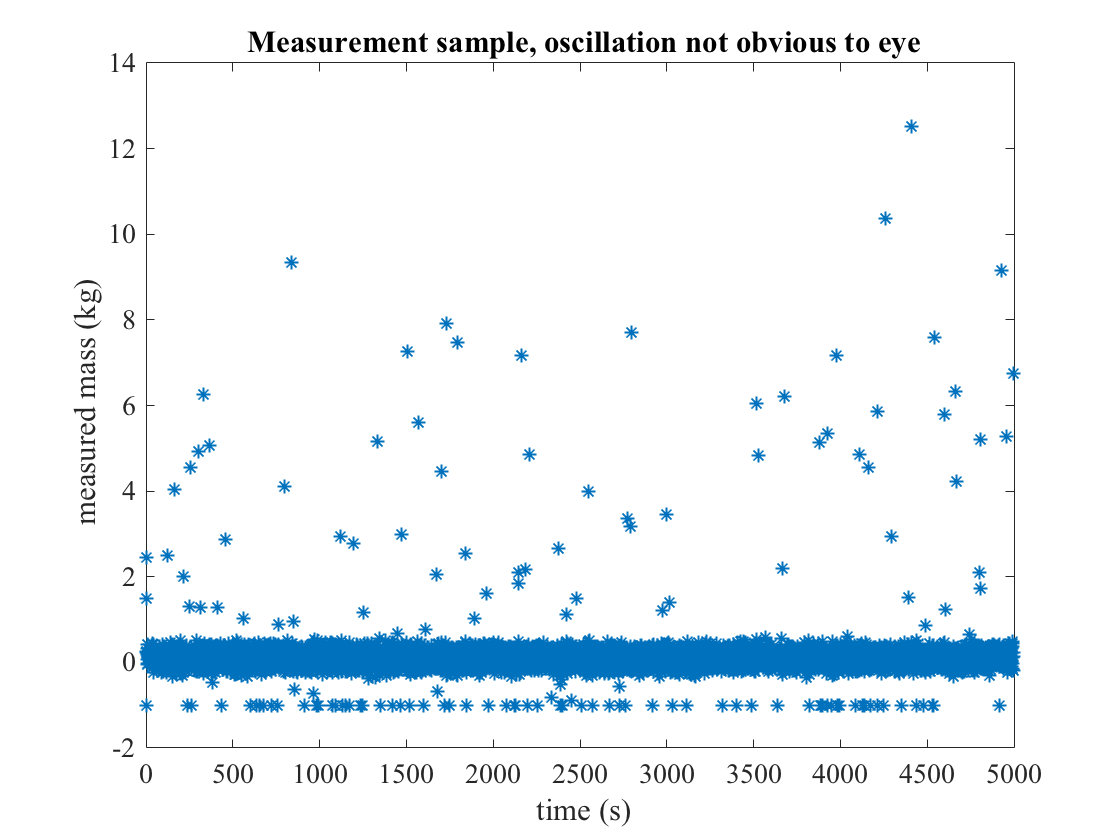

Nsample=5000;         % number of samples        
Fs = 1 ;              % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = Nsample/T;        % Length of signal 
t = (0:L-1)*T;        % Time vector
% Generate the data
y = FakeDataGameGeneratorFunction(mass,t);
figure
plot(t,y,'*')
xlabel(' time (s)');ylabel(' measured mass (kg)');
title(' Measurement sample, oscillation not obvious to eye')

Get the FFT (vector of complex numbers) of that sample. It is a symmetrical function so we fold it and then extract the amplitudes and phases and compute the standard corresponding frequencies.

Y = fft(y); % get fast fourier transform (complex number vector)
Amp2 = abs(Y/L);% amplitude vector of (abs(z))) of each fft value
Amp = Amp2(1:L/2+1);% the first half of the values
Amp(2:end-1) = 2*Amp(2:end-1); %normalize
Phase2 = angle(Y); %corresponding angles
Phase = Phase2(1:L/2+1);
f = Fs*(0:(L/2))/L;% vector of frequencies corresponding to Y

Plot the fft over a narrow range of frequencies near the harmonic signal peak.

figure
range=.15 <f&f<.16; % range=vector of logicals for f satisfying the condition
plot(f(range),Amp(range)) 
title('FFT Spectrum of 1 Hz sample')
xlabel('frequency f (Hz)')
ylabel('|P(f)| (power at each frequency')

 Repeat and superpose on the plot to compare. The noise will be different.

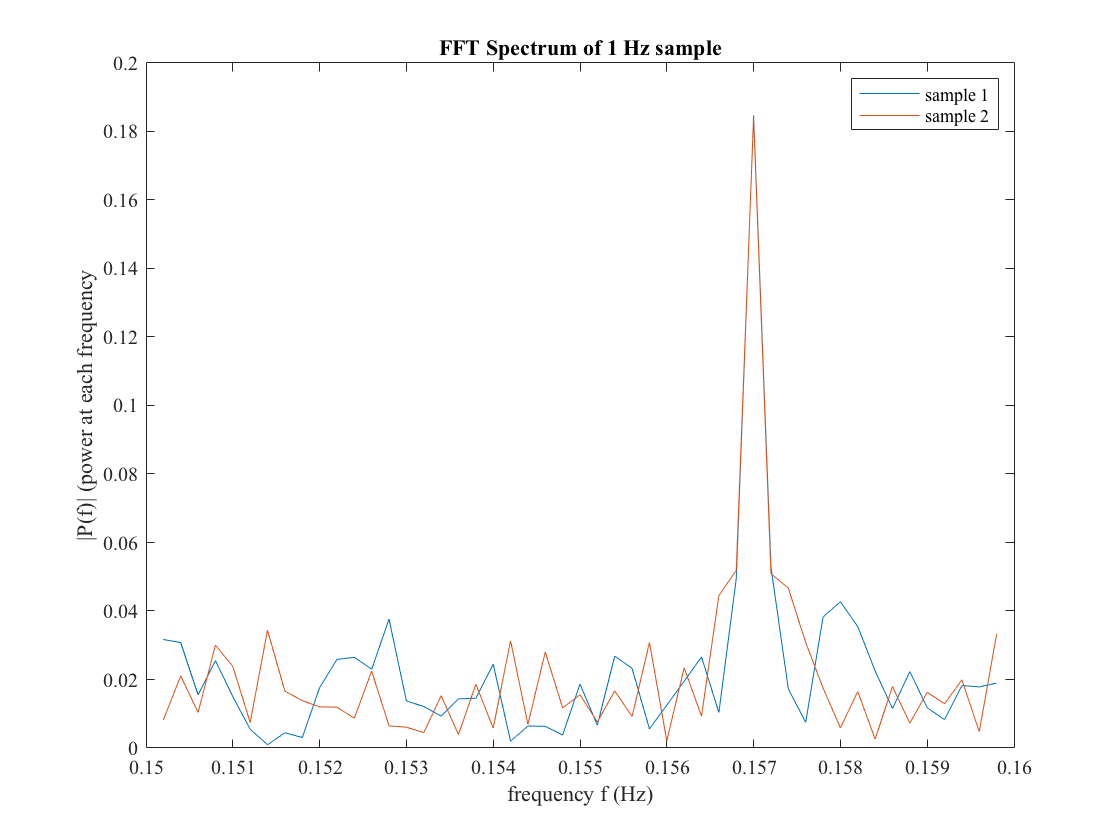

y = FakeDataGameGeneratorFunction(mass,t);
Y = fft(y); % get fast fourier transform (complex number vector)
Amp2 = abs(Y/L);Amp = Amp2(1:L/2+1);% get magnitude (abs) of fft
Amp(2:end-1) = 2*Amp(2:end-1);
Phase2 = angle(Y); % corresponding angles
Phase = Phase2(1:L/2+1);
hold on;% so we can superpose sample 2 on sample 1
plot(f(range),Amp(range)) 
legend('sample 1','sample 2')% add a legend

The spectrum over a narrow range of frequencies is plotted. We see that the FFT identifies an oscillation at about 0.15 Hz. The noise has a flat looking frequency spectrum. Notice the peak appears in both samples with similar power while the noise spectrum varies with sample.  If we used more data, the noise would average to a constant and the amplitude of the peak be better determined.

Note that the frequency of the peak is determined to within +- 1 increment of frequency or +/- (sampling frequency/number of samples) =0.0002 Hz. Assuming a uniform distribution of results possible in each frequency increment, and the fact that the standard deviation of a uniform distribution is 1/sqrt(12) of the interval, we estimate the std of the peak frequency to be (sampling frequency)/(number of samples*3.46).

## Peak finding

The MATLAB function `findpeaks` locates elements in a vector that are larger than neighbor elements and optionally can sort in descending order and plot and superpose labels on peaks in the plot. (See https://www.mathworks.com/help/signal/ref/findpeaks.html.). We will illustrate the capabilities by using `findpeaks` to find the peak in the FFT spectrum to identify the frequency. Later we will apply the algorithm to many spectra.

Find peaks positions lsor in the sample 2 spectrum f, and the values psor, and sort in descending order of amplitude. The first one will be the highest and of most interest, the others due to wee peaks in the transform of the noise.

[psor,lsor] = findpeaks(Amp(range),f(range),'SortStr','descend');

Print out highest peak location, the frequency of the most prominent sinusoidal signal.

peakfreqfindpeaks=lsor(1)%

peakfreqfindpeaks =         0.157

Display atop the previous figure peak-indicating  triangles pointing at identified peaks in the 2nd sample.

findpeaks(Amp(range),f(range))

The `text` command uses plot coordinates to place a string. Convert the sort indices to strings and place on plot near peaks so the most prominent peak is labeled "1" and so on.

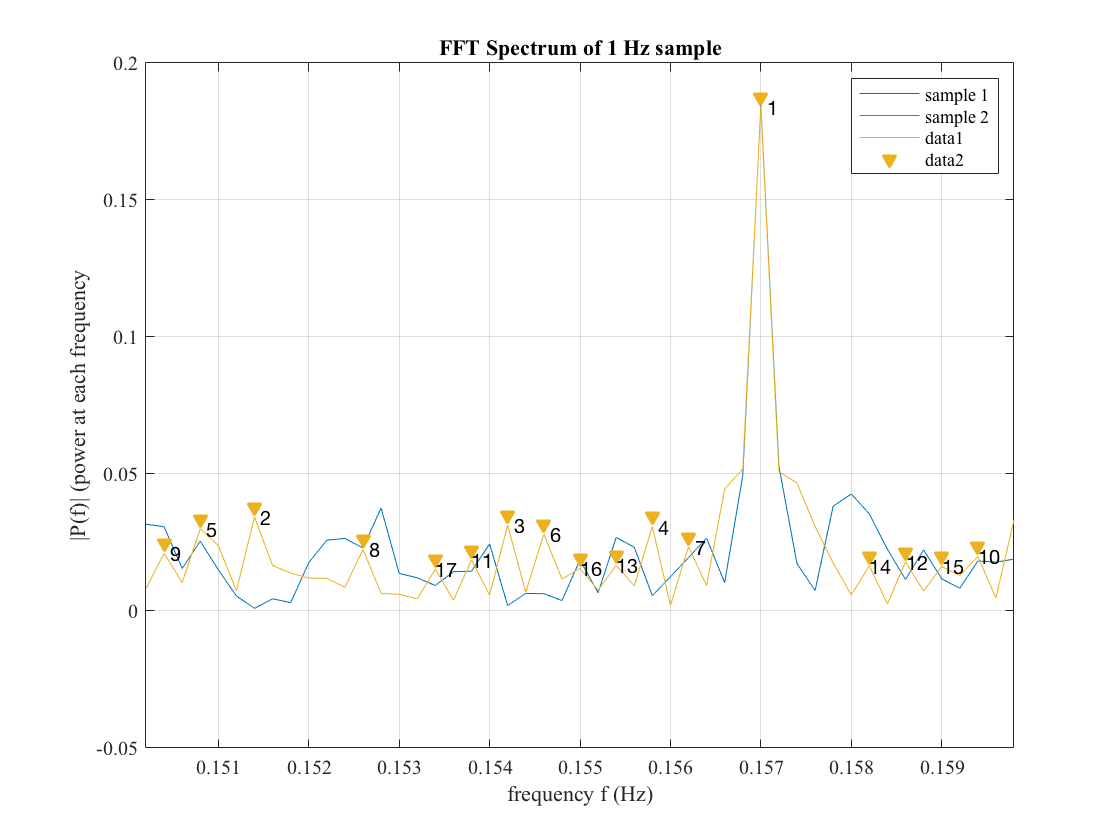

text(lsor,psor,num2str((1:numel(psor))'))

Fours lines of code and, voila: the frequency of peakiest peak is identified and the spectrum is plotted, peaks sorted and labeled. Nice.

`Findpeaks` can identify peaks using a variety of criteria like prominence and distance from other peaks. You may be looking for a peak of certain  shape and avail yourself of findpeaks' flexibility. If the peak of interest is simply that which largest as here, we can simply find value M and index I of largest amplitude using MATLAB's max command.

Our spectrum actually has a large amplitude at zero frequency (Y(1)= the sum of the data points y. `Findpeaks` ignores that half peak. We need to drop that point before using max. Then max gives the index and magnitude of the largest element.

[PeakAmp,PeakIndex]=max(Amp(2:length(Amp)))% max ignoring first dc level

PeakAmp =       0.18402

PeakIndex =    785

We adjust index back by 1 and print  frequency, amplitude, and phase at maximum peak. 

PeakIndex=PeakIndex+1;
freqpeak=f(PeakIndex)

freqpeak =         0.157

amppeak=Amp(PeakIndex)

amppeak =       0.18402

phasepeak=Phase(PeakIndex)

phasepeak =        0.7229

## Fourplot (web search "MATLAB fourplot" for documentation)

The function call `stats=fourplot(x)` makes some standard data quality monitor plots if you have the function installed in your path. The code fourplot.m is attached. It is posted at MATLABcentral. "Run sequence" shows the result values versus measurement number (time). "Lag" is a scatter plot of the the k-th result versus the (k-1)th. For random data, these are uncorrelated. If x results from a function X(t), x(t_n)-x(t_(n-1) is proportional to the derivative of X(t) if X varies slowly on the time scale of the sequence of measurements. If X is periodic, so will be the lag so result in some repeating pattern. "Histogram" shows the distribution of values of x - very important. "Normal probability" compares the data to a normal distribution. It derives from the cumulative sum of the values of X after arranging in increasing order so is like the integral of a histogram of X with no bin having more than one result. It compares that to the expectation for a normal distribution. FYI the inverse of the cumulative (integral) of a probability distribution is a uniform distribution. The "Box plot" shows fractions within a range and flags outliers of a presumed normal distribution.

## Illustration of fourplot

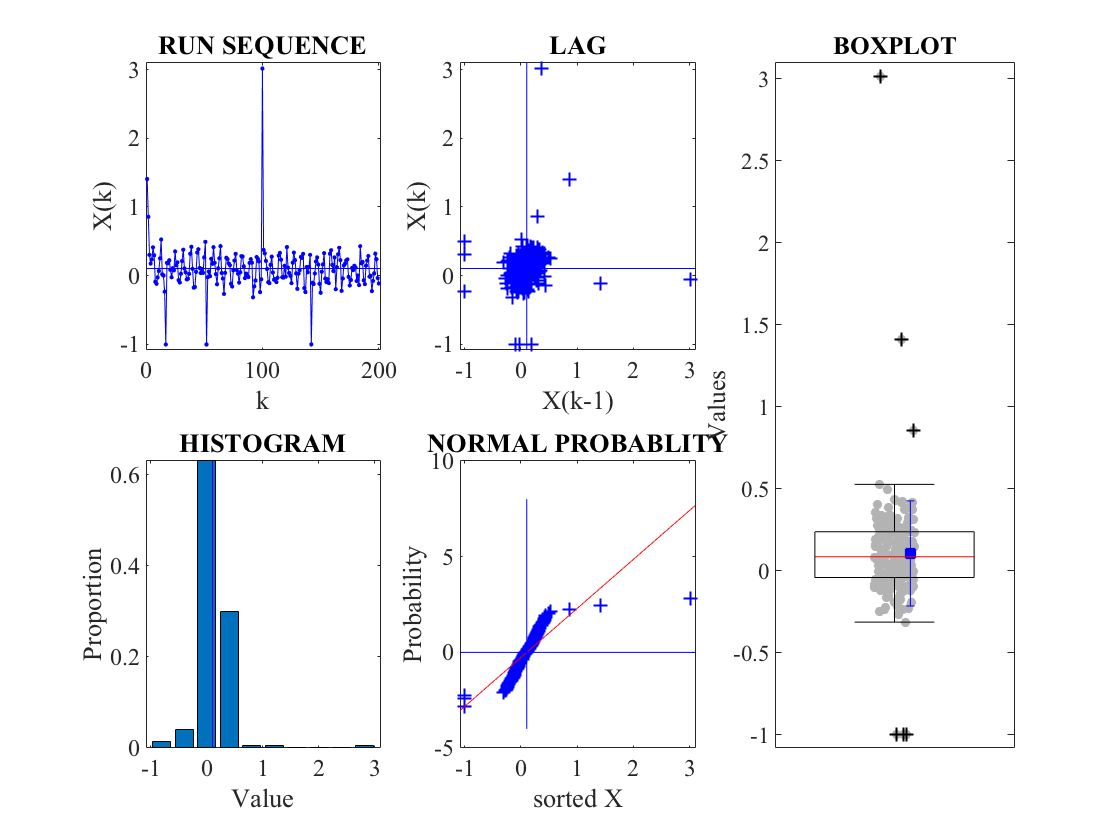

FOUR PLOT
  N     : 200
  Mean  : 0.11
  SD    : 0.32
  Var   : 0.10
  Minimum  : -1.00
  Maximum  : 3.01
  Median   : 0.09
  Q25      : -0.04
  Q75      : 0.24
  IQR      : 0.28
  # outliers below : 3
  # outliers above : 3


n=200;% set number of measurements
t=[1:n];
y = FakeDataGameGeneratorFunction(mass,t);
fourplot(y)

By default,` fourplot` prints the number of parameters, the mean, standard deviation (SD), variance (Var), minimum, maximum, quartile ranges of the input data. It also prints the number of outliers left out of plots. "`stats=fourplot(x);`" suppresses the printed output while saving results in `stats`.

## Initial observations of features and trends in the data.

The following sorts of observations are models for initial analysis of any data set.

There appear points clustered together near the expected value that show a correlation over time, blurred by some random process. There are some wild points occuring only at random times with different unexpected values. Something unique and transient happens at early times: a quick drop in the mean value over the first few seconds. The lag plot indicates some degree of correlation, a blurred oscillation is observed, and the histogram core is bimodal. These oddities may be related. There are occassional random outliers. The mean value settles to a about 0.2 after around 20 s. This value is significantly different than expectation(zero). Even with low statistics, there is evidence for all of these features. Each point is contributing to a story. Always study your plots and make sense of all aspects. See what changes and what is common between samples.

## The next step is to collect more data

We want to see if the observations are born out as characteristic, or were just flukes. We have already for purposes of illustration tried shorter times and discovered an oscillation. Try next a middle size mass and a large mass. You should first find the dynamic range given in the operating manual or by careful exploration, in order to not damage the instrument. Too high a mass could break a mass scale. To high an input voltage may ruin an electronic instrument. If you play with FakeDatGameGenerator, you can discover its range is a bit below zero to something above 10 kg.

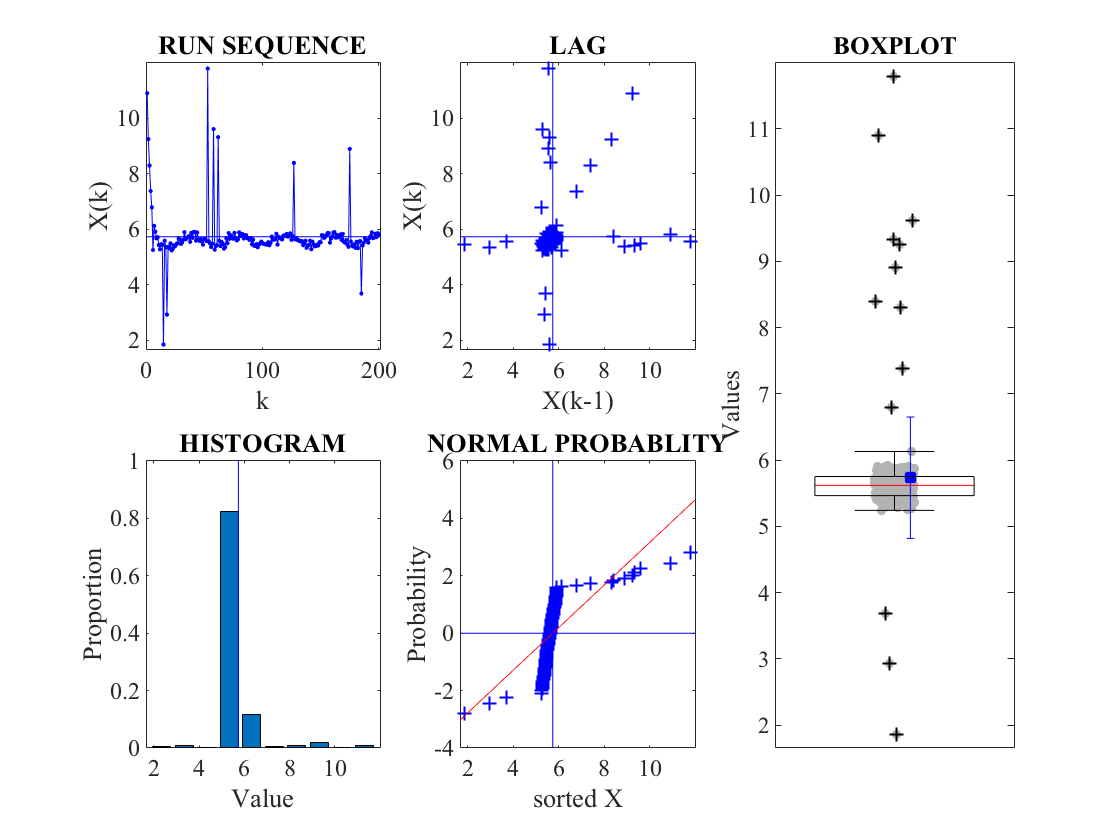

mass = 5;
y=FakeDataGameGeneratorFunction(mass,t);stats=fourplot(y);

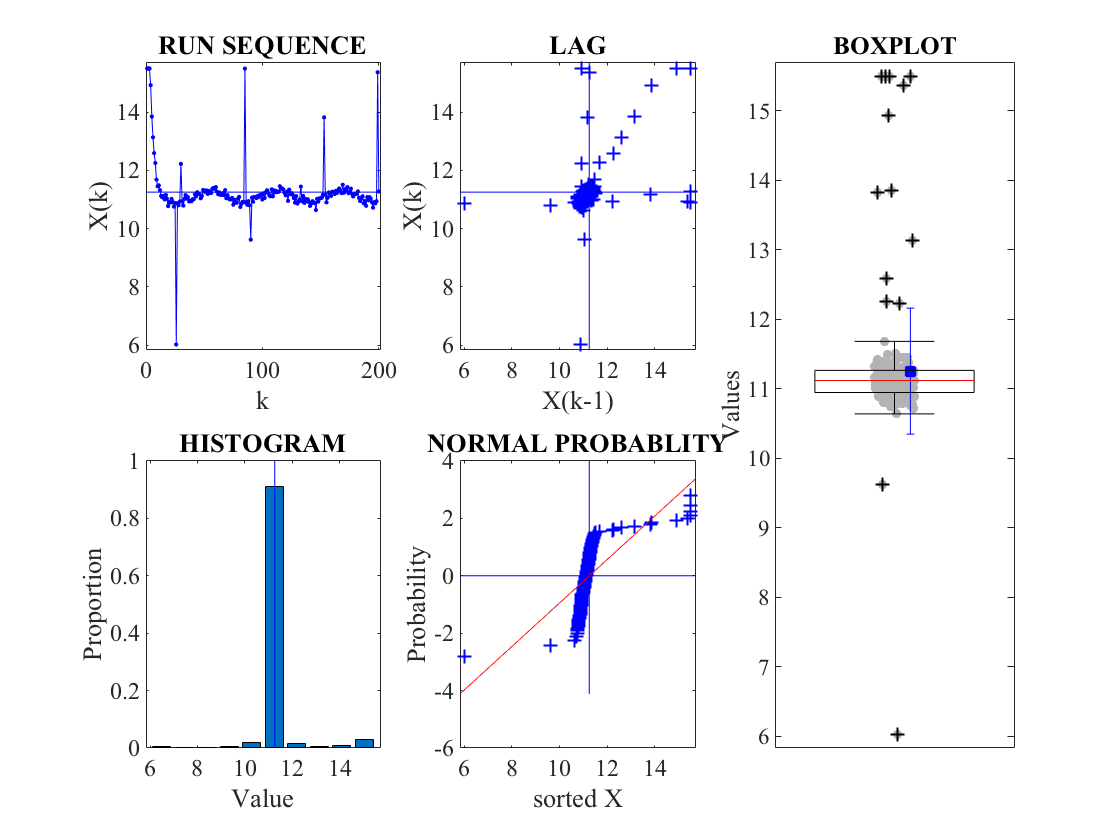

mass = 10;
y=FakeDataGameGeneratorFunction(mass,t);stats=fourplot(y);

We can see similar but more pronounced effects as seen for zero mass.  For mass=5, the result settles down to a value more than 0.5 above the expected value, more than we saw with zero mass. That is a significant observation born out in the m=10 data. After 20 s, there is always evidence of oscillation and noise. The oscillation amplitude and noise level look to be independent of mass.  The oscillation frequency however is mass dependent. These are significant new observations.

## Make a hypothesis about the structure of the data

The data seems to have the form $y(t)= f(t)+rand1+rand2$ where $f(t)$ roughly drops to a constant plus an oscillation, rand1 is random jitter present at every reading, and rand2 is a random large jitter affecting only a random fraction of readings. This set of hypotheses needs testing.

## Explore each hypothesis in turn by narrowing your inquiry

Focus on the easy steady part. Let's start by waiting 20 seconds after we put the weight on to let the mechanism settle down. Let's also filter out the spurious results (rand2) by replacing results that are well away from their nearest neighbors, or from the steady sample average, with their nearest neighbor average or with the sample average if the neighbors are contaminated also by chance. That will leave perhaps some small rand2 glitches immersed in the data but their number and impact will be much smaller. 

This custom "filtering" plan is implemented in a function `filterdata` below. It is implemented as a function so we can reuse the code repeatedly. The threshold value for distance of a spurious event from the mean to qualify as spurious is passed to the function as a parameter.

In your own data analysis, you may want to write your own filter. MATLAB has some fancy progressive algorithms but we will stick to simple, but we have been test it. A sliding window averaging filter appropriate to averaging the gaussian noise but not the outliers is presented as an example in

[https://www.mathworks.com/help/coder/examples/averaging-filter.html](https://www.mathworks.com/help/coder/examples/averaging-filter.html) 

which also describes how to generate a c-language version of the filter automatically and compile it for reuse as a binary (faster than interpreting the MATLAB). To get a sense of c-code, you might run through this example.

MATLAB provides a variety of methods for data smoothing and outlier identification. An app exploiting some of these methods is at

[https://www.mathworks.com/matlabcentral/fileexchange/65343-ugly-data-app](https://www.mathworks.com/matlabcentral/fileexchange/65343-ugly-data-app)

and the help in the app provides links to the functions. Code generated by this app interactively may be saved for reuse or modification by you.

We could reuse the later part of the data in hand but on a computer can simply call the simulation again, sending the simulation function a delayed first measurement time.

## Test the filter

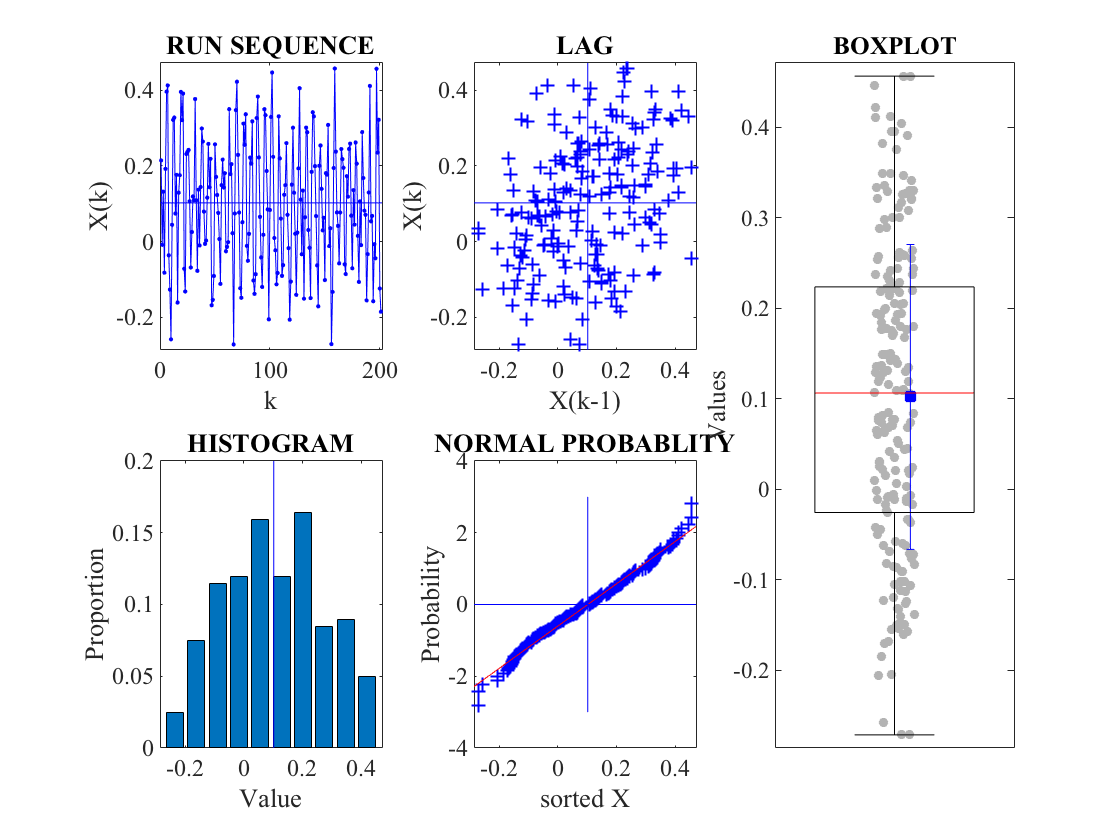

FOUR PLOT
  N     : 201
  Mean  : 0.10
  SD    : 0.17
  Var   : 0.03
  Minimum  : -0.27
  Maximum  : 0.46
  Median   : 0.11
  Q25      : -0.03
  Q75      : 0.22
  IQR      : 0.25
  # outliers below : 0
  # outliers above : 0


 tdelay = 20;% time delay
 t=[tdelay:tmax+tdelay];% sequence of times after initial time delay
 mass=0;
 y=FakeDataGameGeneratorFunction(mass,t);
 % Apply filter now
 threshold=0.5;% the min absolute value of deviation to filter.
 y=filterdata(y,mass,threshold);
 fourplot(y)

## Observations after applying a filter

For mass=0, we can better see and determine a shifted mean. The number of outliers has gone to zero. Rand2 events no longer skew the limits of the plots.

## Test on other masses

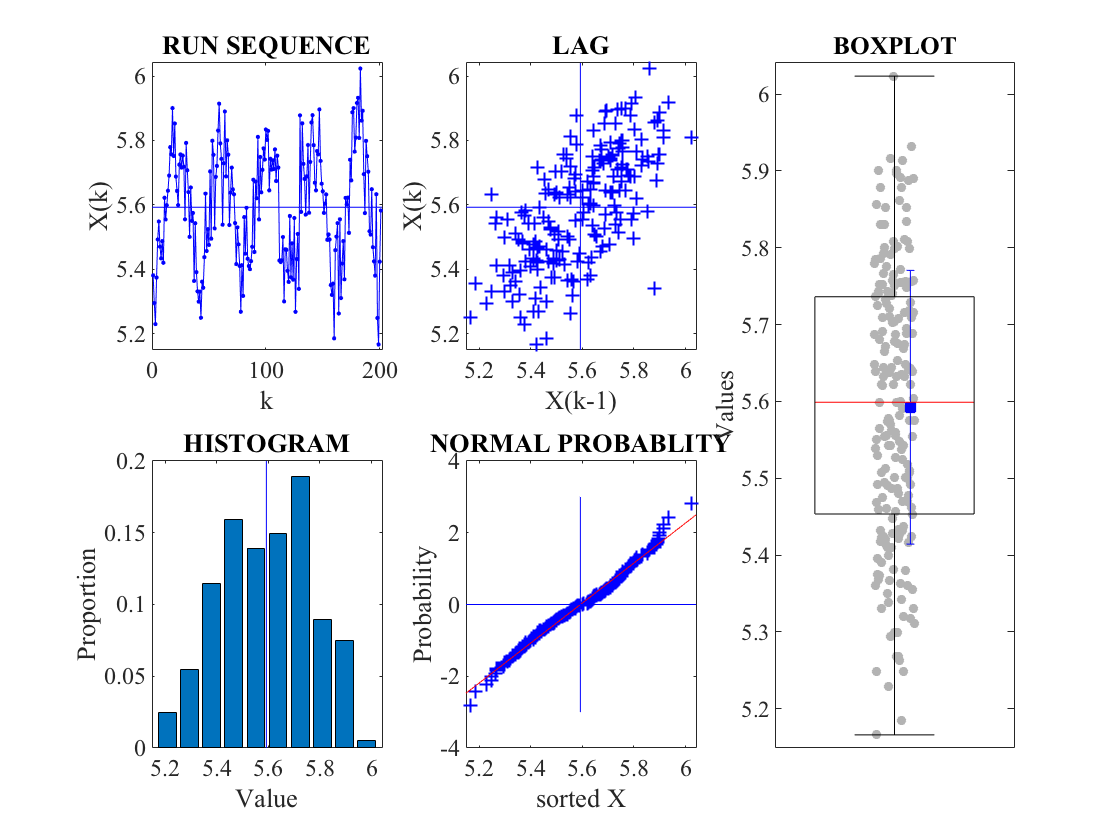

 mass=5;
 y=FakeDataGameGeneratorFunction(mass,t);
 y=filterdata(y,mass,threshold);stats=fourplot(y);

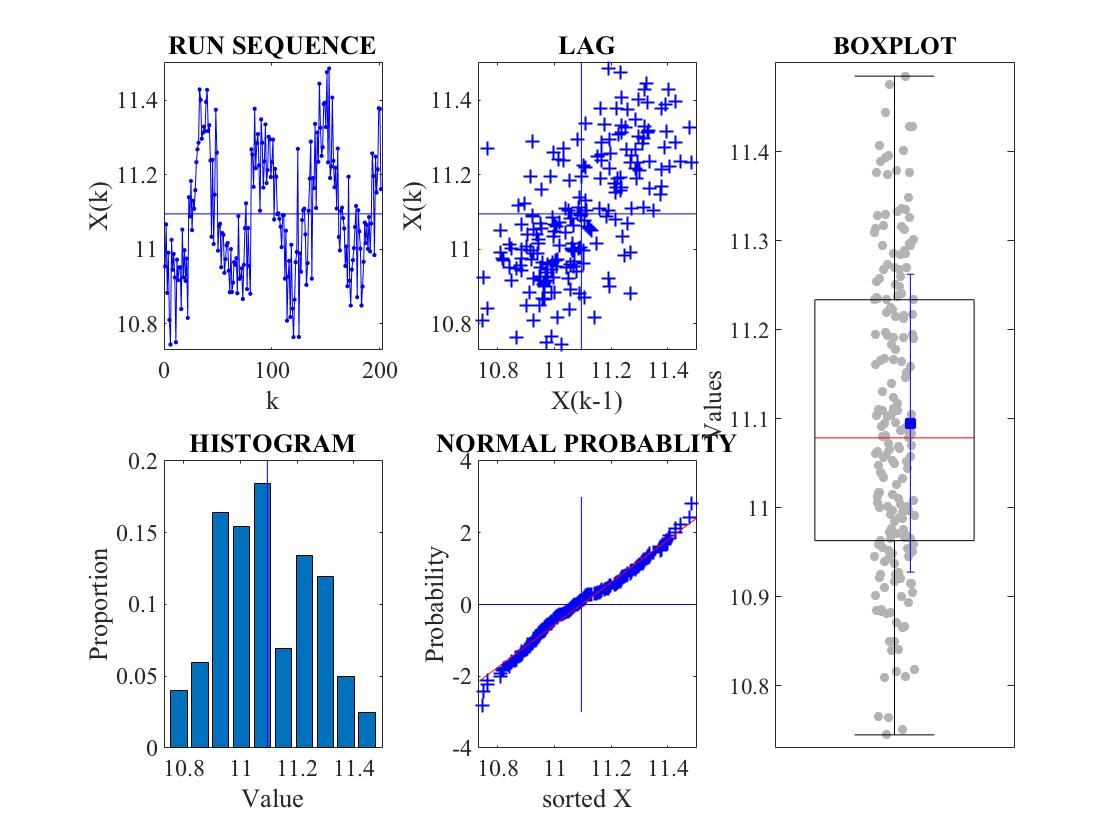

 mass=10;y=FakeDataGameGeneratorFunction(mass,t);
 y=filterdata(y,mass,threshold);stats=fourplot(y);

The filter continues to work. The mean results for m>0 appear offset from expectation by amounts increasing with mass, and there is a persistent oscillation evident in all of the fourplot plots that is having a significant impact on the measured values.  

Note better evidence for mass dependence of oscillation.

## Study of the mean values and frequencies.

Let's be systematic and use a number of different masses and plot the filtered sample mean and standard deviation versus mass. Note we use the MATLAB functions `mean `and `std` which quickly compute mean and standard deviation of an array. We will also perform an fft on each sample and extract the oscillation frequency.

Fs = 10;              % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = 10000;            % Length of signal
t = (0:L-1)*T;        % Time vector
tsave = t+20;         % Save for future use
figure                % for plot of fft's

The following is an example of a loop structure. The code between the `for` and `end` is executed for each value of `imass`. We use a loop to repeat our adhoc analysis for 11 masses.

for imass=1:11 % loop over mass choices
     testmass(imass)= imass-1;% masses will be [0:10] and saved
     y=FakeDataGameGeneratorFunction(testmass(imass),t+20);
     y=filterdata(y,mass,threshold);

Get the mean and standard deviation from the mean of the sample and store in arrays.

     meanmass(imass) = mean(y);
     stdmass(imass) =  std(y)  

Save the data in big array, one column per mass for later use. We equate rows of an array Ymass to the data for the given mass

     Ymass(:,imass)=y; 

Get FFT but subtract mean to kill the (DC/zero freq) component half peak. This will help in plotting the FFT - we will see just the nonzero frequency peaks.

     Y = fft(y-meanmass(imass));
     Amp2 = abs(Y/L);
     Amp = Amp2(1:L/2+1);
     Amp(2:end-1) = 2*Amp(2:end-1);% amplitude
     Phase2 = angle(Y); % corresponding phase angles
     Phase = Phase2(1:L/2+1);
     f = Fs*(0:(L/2))/L;
     % Define range of frequencies to plot.
     % Our oscillation signal frequencies are < 1 Hz.
     range=f<0.2;
     % plot power versus frequency over the restricted range range
     plot(f(range),Amp(range));hold on 
     xlabel('frequency f (Hz)')
     ylabel('|P(f)| (power at each frequency')
     title(' Frequency spectra for various masses')
     [psor,lsor] = findpeaks(Amp(range),f(range),'SortStr','descend','Threshold',0.02);
     freqmass(imass)=lsor(1);

Estimate and save the freq measurement std. 

     freqstdmass(imass)= Fs/(L*3.46);
     label = strcat('m=',num2str(testmass(imass)));
     text(lsor,psor,label);

Save frequency, amplitude, and phase at maximum peak, find value M and index I of largest amplitude kill dc level. `findpeaks` ignores 0 as the value has no lesser neighbor

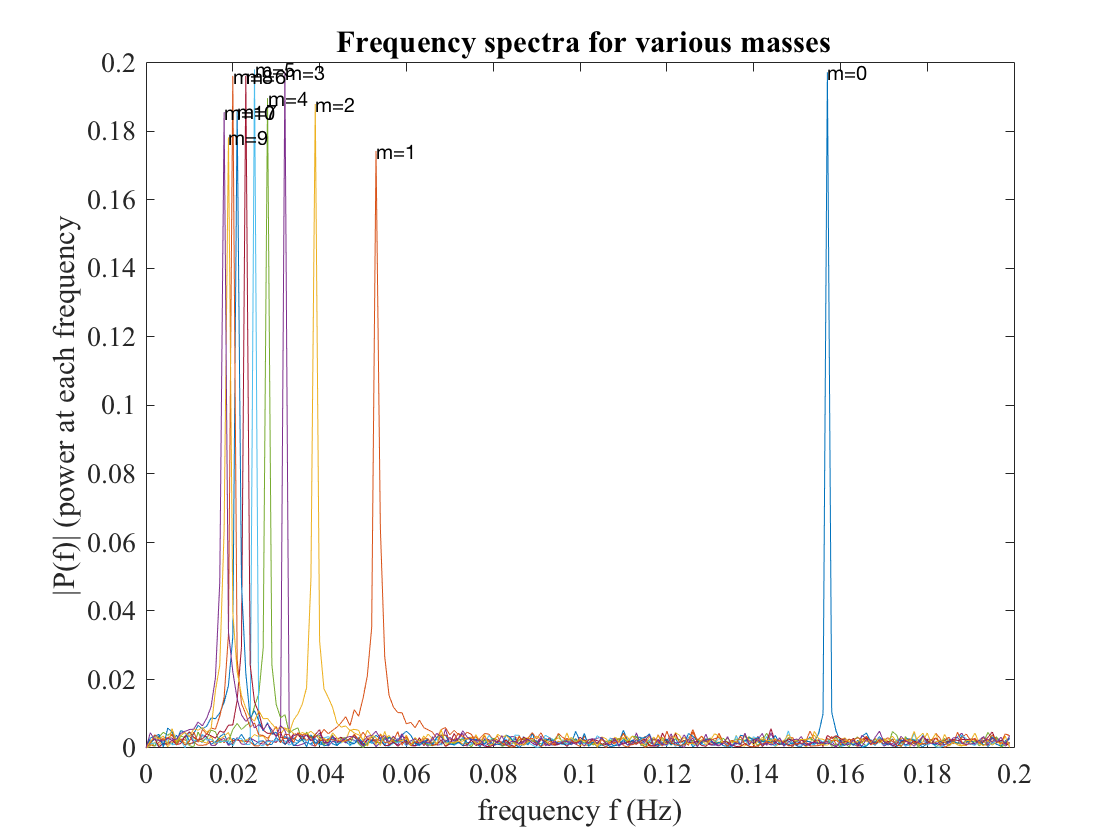

stdmass =       0.17136

stdmass =       0.17136      0.17172


stdmass =       0.17136      0.17172       0.1731


stdmass =       0.17136      0.17172       0.1731      0.17195


stdmass =       0.17136      0.17172       0.1731      0.17195       0.1712


stdmass =       0.17136      0.17172       0.1731      0.17195       0.1712      0.17193


stdmass =       0.17136      0.17172       0.1731      0.17195       0.1712      0.17193      0.17397


stdmass =       0.17136      0.17172       0.1731      0.17195       0.1712      0.17193      0.17397      0.17293


stdmass =       0.17136      0.17172       0.1731      0.17195       0.1712      0.17193      0.17397      0.17293      0.17488


stdmass =       0.17136      0.17172       0.1731      0.17195       0.1712      0.17193      0.17397      0.17293      0.17488      0.17391


stdmass =       0.17136      0.17172       0.1731      0.17195       0.1712      0.17193      0.17397      0.17293      0.17488      0.17391      0.17289


     Amptemp(1)=0;
     Amptemp=Amp(range);
     [M,I]=max(Amptemp);
     Freqmass(imass)=f(I);
     Ampmass(imass)=Amp(I);
     Phasemass(imass)=Phase(I);
end% end of loop of masses

## Look at values of collected statistics

 meanmass 

meanmass =       0.10151          1.2       2.3013       3.4015       4.5005       5.5991       6.7025       7.7991       8.8994       10.001       11.099


 stdmass 

stdmass =       0.17136      0.17172       0.1731      0.17195       0.1712      0.17193      0.17397      0.17293      0.17488      0.17391      0.17289


 freqmass

freqmass =         0.157        0.053        0.039        0.032        0.028        0.025        0.023        0.021         0.02        0.019        0.018


 freqstdmass

freqstdmass =    0.00028902   0.00028902   0.00028902   0.00028902   0.00028902   0.00028902   0.00028902   0.00028902   0.00028902   0.00028902   0.00028902


 Ampmass

Ampmass =        0.1973      0.17429      0.18805       0.1974      0.18976      0.19816      0.19625      0.18612      0.19624      0.17828      0.18565


 Phasemass

Phasemass =        1.0335       1.2481       -2.039      -2.2369       3.0613       3.1366       2.4713      -2.9797       2.0561       1.5261       1.5925


The means are above expectation by ~ 10 percent with an offset even at m=0. The stds are constant. The frequencies are monotonically decreasing with mass nonlinearly. The amplitudes of the sinusoidally signal are consistent with constantbut affected by the noise. The phases appear random, but FFT has trouble with phases...

## Plot mean and std together to look for trends

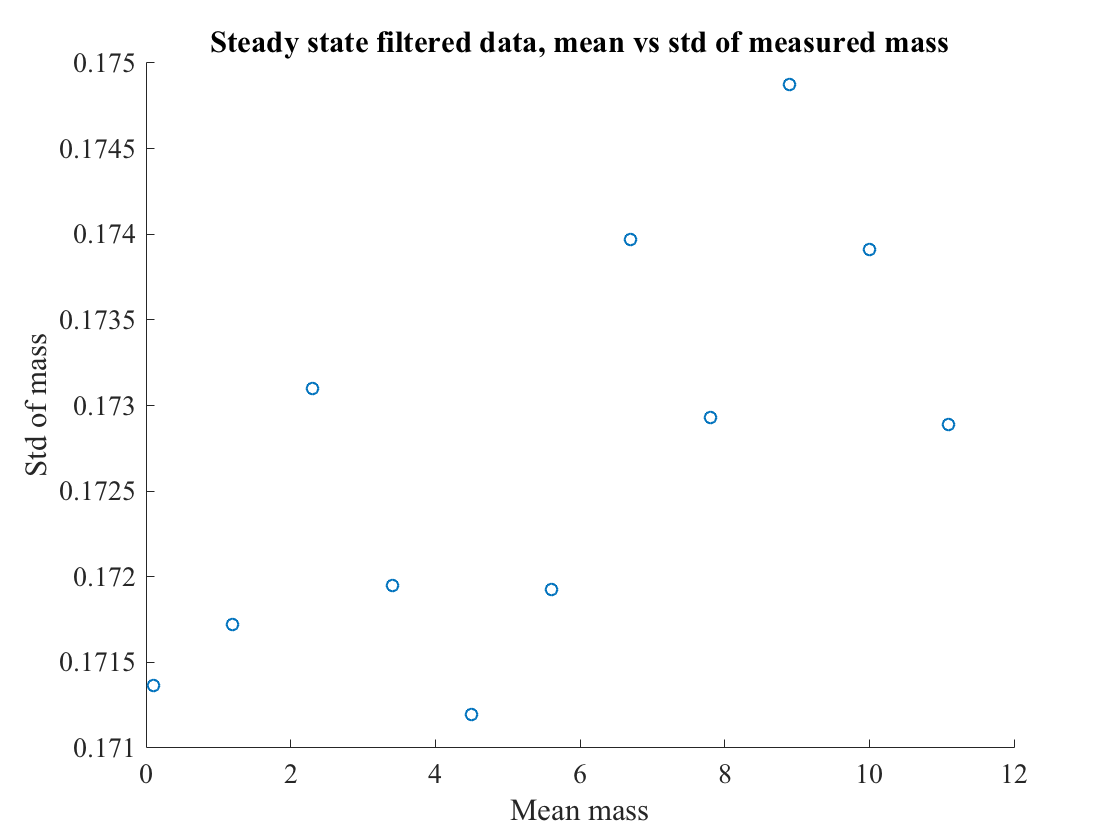

figure
scatter(meanmass,stdmass);
title('Steady state filtered data, mean vs std of measured mass')
xlabel('Mean mass');ylabel('Std of mass')

Note the supressed zero. The stds have similar value. There is no obvious trend in std versus mass.  That must mean the random noise standard deviation rand1 and the amplitude of  oscillation of f(t) are both also constant, or there is some coincidence that makes the sum have constant std.

## Let's plot the mean values versus mass.

The MATLAB function `errorbar` is used to show the range around each mean corresponding to 1 standard deviation. We plots points with no lines that might guide the eye as we will later superpose a fit. We will also superpose scaled residuals to the fit.

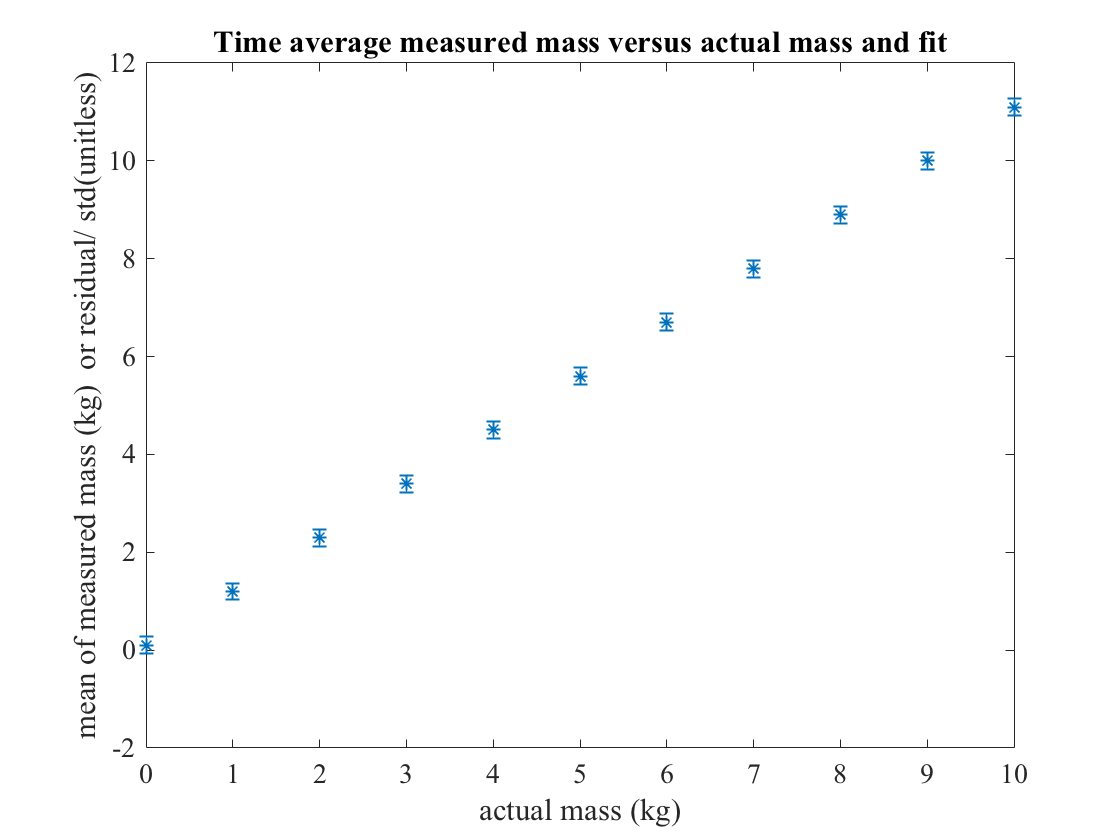

figure
errorbar(testmass,meanmass,stdmass,'*','LineStyle','none');
xlabel('actual mass (kg)');
ylabel('mean of measured mass (kg)  or residual/ std(unitless)')
title('Time average measured mass versus actual mass and fit')

There is clearly an approximately linear relationship between the mean of the steady state filtered results and the actual mass, and a small offset at zero mass.

## Fit time average mean mass versus actual mass

We will use a least-squares-method polynomial fit to a quadratic form using the MATLAB function `polyfit` specifying a degree 2 polynomial model function with three parameters of the form y(x)=p(1)*x.^2 + p(2)*x + p(3). The fit minimizes the sum of the squared deviations of predicted values from the data points.

display('Polyfit to mean mass observed vs calibration mass.')

Polyfit to mean mass observed vs calibration mass.


Get fit parameters p and print parameters.

[p] = polyfit(testmass,meanmass,2) 

p =   -1.3013e-05          1.1      0.10105


% options=fitoptions('poly2');

Superpose fit results on the plot to see if the fit worked.

x=[0:10]; % mass values used
yfit=p(1)*x.^2 + p(2)*x + p(3);% compute values using fit parameters
hold on; 
plot(x,yfit)

Plot residuals of fit divided by std of noise and multiply by ten to make visible

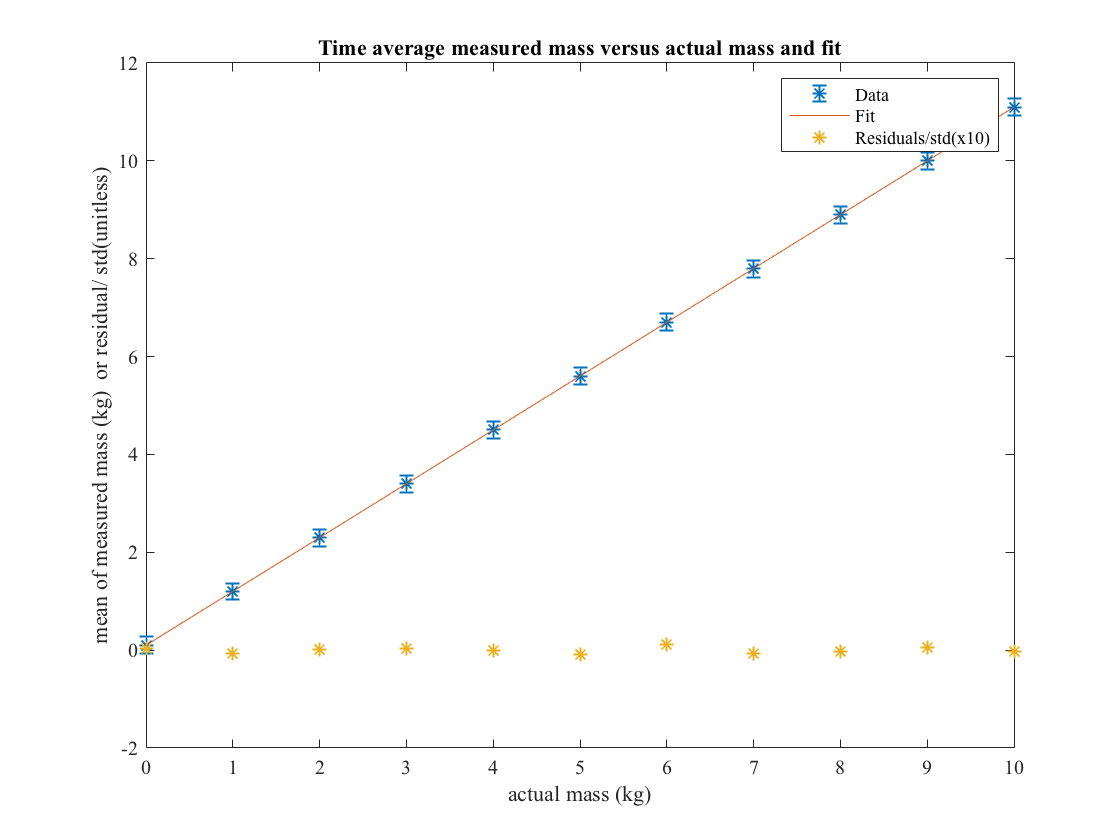

plot(x,10*(meanmass-yfit)./stdmass,'*')
legend('Data','Fit','Residuals/std(x10)');
% see plot and documentation for "legend"
hold off

## Check fit quality. It should be neither too good nor too bad.

That a curve is subjectively close to describing data is sometimes sufficient information. But to say it "agrees" with the data means in science it is consistent in a statistical sense, matching the data within expected fluctuations, a much stronger statement. This stronger statement really a test of the hypothesis  that the data match the curve as well as and no better than could be expected. 

It is important you always plot data points with error bars in order to test such a hypothesis. Our fit passes within ~ 1 std of most points. If the stdmass described normally distributed noise, the noise at each point in time independent of the noise at other points in time, we would expect ~30% of points to be more than 1 std from the actual curve. Our fit is too good. Why? Because the stdmasss values are std's of sinusoidal variations of fixed amplitude plus normally distributed noise. The meanmass values have an std governed by averaging principally the noise alone (the sinusoidal variation averages to zero) over the number of measurements n so an std of about std_noise/sqrt(n). So we should not suggest to anyone that the errorbars shown are representative of the time averaged means shown. They are representative of single measurements.

An aside (reality check): The parameter p(3) is a mass independent zero offset and is within 0.003 of the zero offset =0.1 in the simulation. The parameter p(2) sets the scale. The fit gives p(2)-1 =0.0977 which is within 0.003 of the simulation parameter scaleoffset=0.1. These agreements would be improved with more data. WIth a real scale with a mechanical pointer, the zero is the position of the pointer with zero mass on the platform. It may change with mechanical wear and is sometimes adjustable with a turn screw. The scale factor governs the angle of the pointer per unit mass. A mass produced scale has an indicator dial mass produced to best match all of the units produced but it won't necessarily be correct for any particular unit.

**Conclusions from linearity study**

It does appear the means versus mass are linearly related. We see that p(1), the coefficent of the quadratic term, is neglible (small value comparable to error) so we can drop this term. The simulation in fact assumes a linear spring. At large stretch, any spring will have a nonlinear response so our test is not trival. 

Let's hypothesize spring nonlinearity is not measureable. This hypothesis could be tested by comparing the chisquares for fits with and without a quadratic term. Chisquared ($\chi^2$)is the sum of residuals squared and should have a value of about  $n-n_{dof}$ for n measurements and a fit with $n_{dof}$ parameters. If adding a parameter fails to improve chisquare significantly, it does not help predict the data and is likely not a important parameter of a underlying model. But we don't very well understand the errors yet so let's move on to assume our fit provides a good calibration curve and test this calibration curve.

## Make some filtered delayed data and test the fitted calibration curve

n=100; mass = 5;
t=[20:n];
y=FakeDataGameGeneratorFunction(mass,t);
y=filterdata(y,mass,threshold);

Correct using calibration by subtracting the offset and adjusting the slope.

ycorr = (y -p(3)*(t./t))/p(2);

Plot the corrected data.

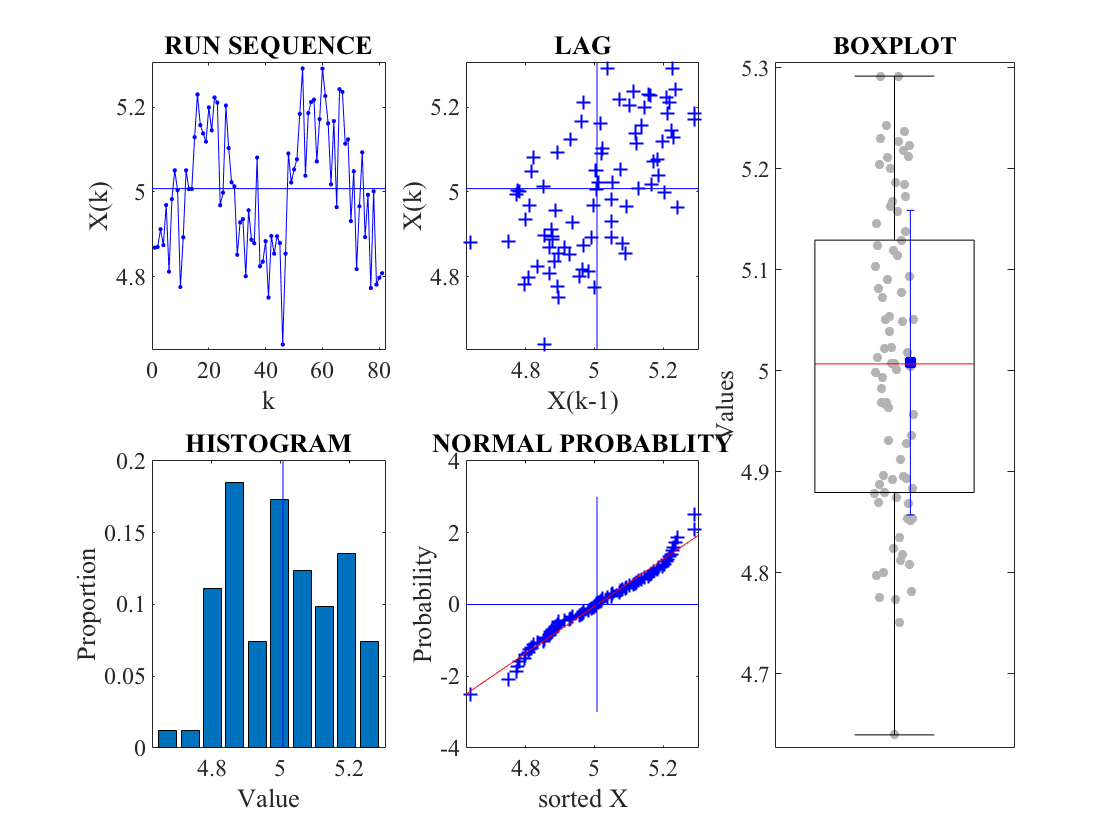

stats=fourplot(ycorr);

The mean is now centered at the expected value.  The plot of mass v time shows the slow oscillation we averaged. The lag plot shows some random uncorrelatedpoints but also a diagonal line of correlated points likely due to the oscillation. 

Let's try to understand this oscillation better.

## Study of mass dependence of frequency.

We extracted previously the oscillation frequency at each mass. Plot frequency vs mass.

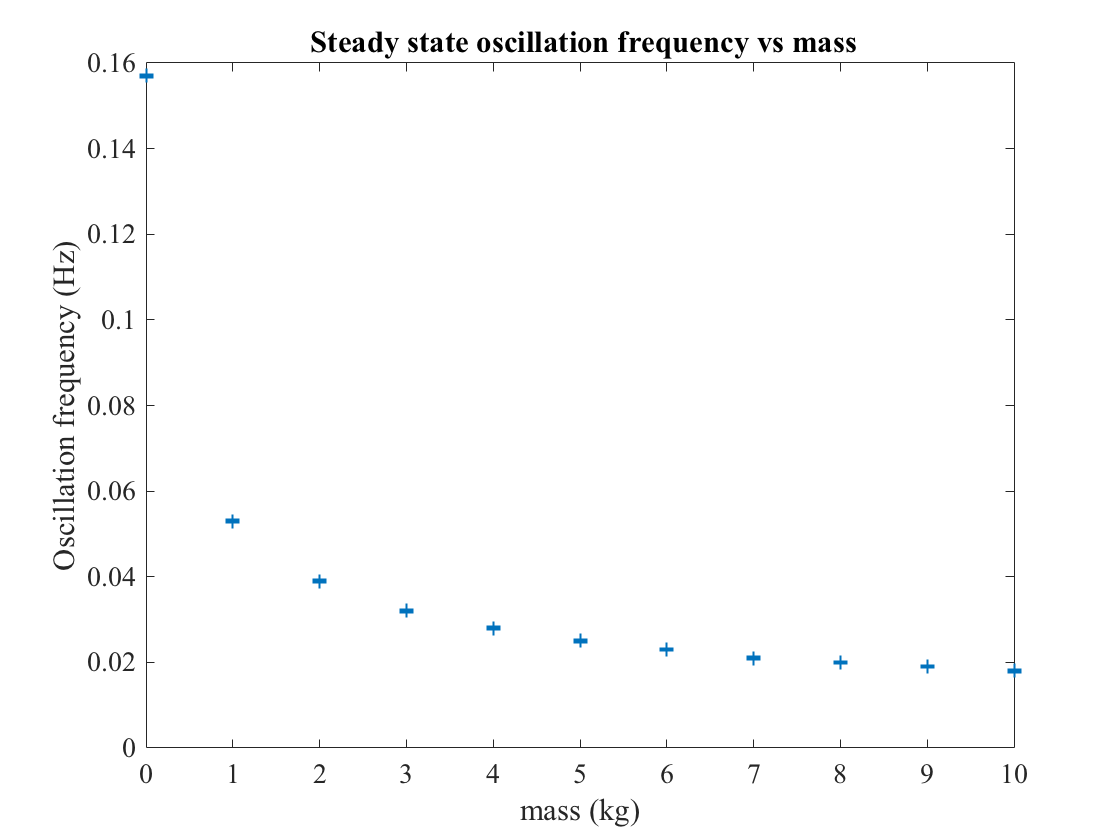

figure
errorbar(testmass,freqmass,freqstdmass,'+','LineStyle','none')
xlabel('mass (kg)');ylabel('Oscillation frequency (Hz)');
title(' Steady state oscillation frequency vs mass')

Observe that the frequency is a decreasing function of mass. We could simply parametrize this but it is time to stop and think...

## Model dependence of frequency on mass

As we will learn in physics, the natural frequency of oscillation of a mass on a spring of spring constant k is $f(m)=\sqrt(k/(m+m_{dead}))/(2\pi)$where $m+m_{dead}$ is the total mass on the spring. The freqeuncy is a decreasing function of mass for fixed k. It looks like the observed oscillations follow this form. For zero mass on the platform, there is still platform mass, $m_{dead}$. Let's fit the frequency data to this form accounting for dead mass. We use a nonlinear fitting method, defining a model function for frequency `modelfun = sqrt(b(1)/(mass+b(2)))/(2*pi)` where `b(1)` = the spring constant k and `b(2)` is the dead mass. 

Let's first estimate these quantities from the frequency data in hand. We have $(2\pi f)^2 = b(1)/(m+b(2))$. Hence, $b(1)-(b(2)+m)(2\pi f)^2=0$. If we pick two masses `m1` and `m2`, and their frequencies `f1` and `f2`, we have two equations that we can solve uniquely for `b(1)` and `b(2)`. Write those two equations in MATLAB matrix form a*b=c as

`a(1,1)*b(1)+a(1,2)* b(2)=c(1)= m1*w1; a(1,1)=1,a(1,2)=-w1;w1 = (2*pi*f(m1))^2 a(2,1)*b(1)+a(1,2)* b(2)=c(2)=m2*w2; a(2,1)=1,a(2,2)=-w2;w2 = (2*pi*f(m2))^2 .`

The solution (using the inverse 1/a of the matrix a) is `[b(1);b(2)]= (1/a) [m1*w1;m2*w2].` Let's try it.

m1=1;m2=2;f1=freqmass(2);f2=freqmass(3);w1=(2*pi*f1)^2;w2=(2*pi*f2)^2;
amat=[1 -w1;1 -w2]; 
b=[0;0];

MATLAB inverts matrices for breakfast.

b=inv(amat)*[m1*w1;m2*w2]

b =       0.13096
       0.1809


We find k~0.13 N/m and mdead~0.18 kg. Repeat with a different mass pair.

m1=0;m2=2;f1=freqmass(1);f2=freqmass(3);w1=(2*pi*f1)^2;w2=(2*pi*f2)^2;
amat=[1 -w1;1 -w2]; 
b=[0;0];
b=inv(amat)*[m1*w1;m2*w2]

b =       0.12799
      0.13153


We find similar results for k.  The m1=0  pair is probably most sensitiveto the dead mass. This model seems to work!

## Fit model for mass dependence of oscillation frequency

Let's use these as initial estimates in a nonlinear fit to frequency versus mass to get the best estimates using all the data we just simulated. This is really a showcase fit. We are going to ultimately simulutaneously fit thousands of data points to a truly nonlinear model for which the unsual least squares linear model techniques fail. We will start by fitting a nonlinear model to the mass dependence of frequency to extract the best estimate of the deadmass and spring constant from all the values described and plotted above.

Set the initial estimates

b0=b;

Define an (anonymous) model function for the fitter to call

modelfun = @(b,testmass)( sqrt(b(1)./(testmass+b(2)))/(2*pi) );

Now use the "fit nonlinear model" MATLAB command `fitnlm` to do the fit, giving it the masses, frequencies, name of the function to call to predict masses, and initial values of the parameters in the model function. It will change these parameters to minimize the chisquared between the data and the model using an iterative method.(If a small  change reduces chisquare, keep that change. Else try the other direction of change until both directions increase chisquared.)

mdl = fitnlm(testmass,freqmass,modelfun,b0)

mdl = Nonlinear regression model:
    y ~ (sqrt(b1/(testmass + b2))/(2*pi))

Estimated Coefficients:
          Estimate        SE        tStat       pValue  
          ________    __________    ______    __________
    b1    0.12685      0.0005357    236.79    2.1741e-18
    b2    0.13037     0.00064096     203.4     8.538e-18

Number of observations: 11, Error degrees of freedom: 9
Root Mean Squared Error: 0.000186
R-Squared: 1,  Adjusted R-Squared 1
F-statistic vs. zero model: 4.82e+05, p-value = 2.31e-23

To learn how to retrieve the results, see [https://www.mathworks.com/matlabcentral/answers/234468-how-do-i-print-save-parameters-from-fitnlm.](https://www.mathworks.com/matlabcentral/answers/234468-how-do-i-print-save-parameters-from-fitnlm.) The returned values of the parameters are given by the following expression  which returns a vector for the b parameters it saved in a "model" data structure internally. We equate that to a local vector b to save the estimates just printed out.

b = mdl.Coefficients.Estimate ; 

and save the parameters for future use.

mdead=b(2);springconstant=b(1);

The returned fitted parameters have values similar to our estimates using just two points but have used all of the data.

Plot the fit atop the results derived from experiment.

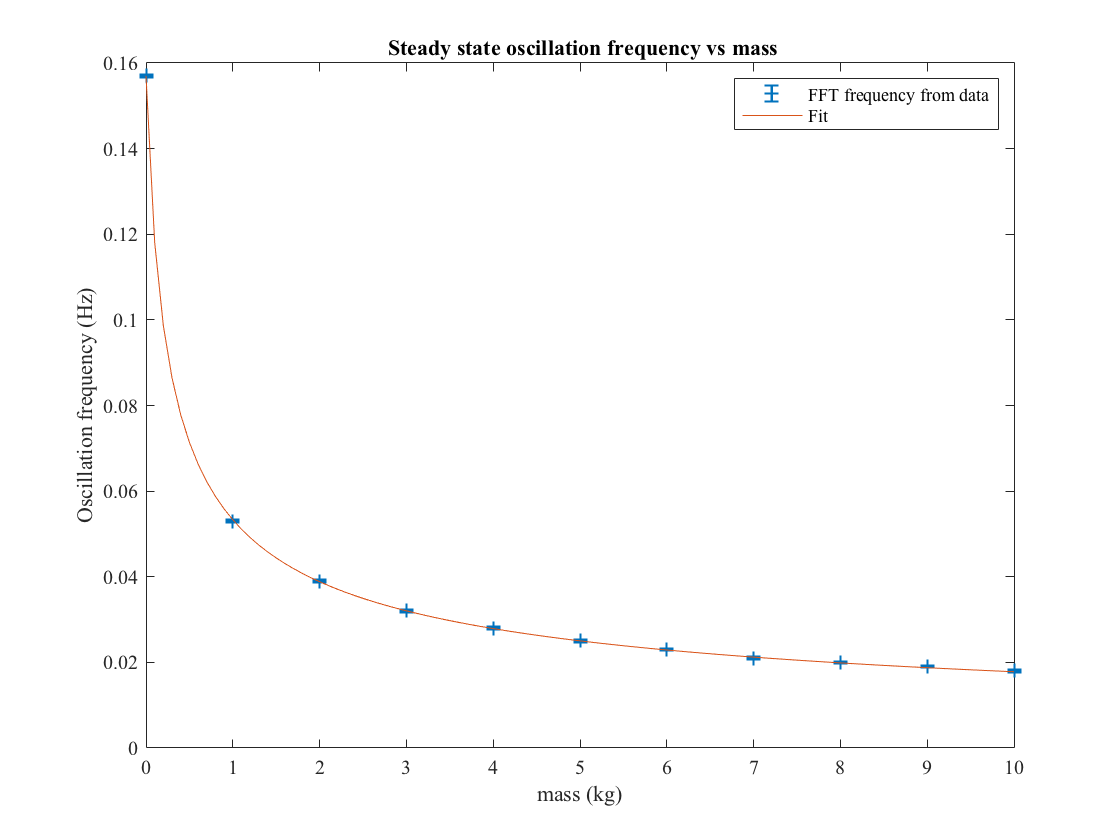

fitmass=[0:.1:10];% a vector of masses
modelfit = sqrt(b(1)./(fitmass+b(2)))/(2*pi); % corresponding function values
hold on; % so we can superpose not overwrite
plot(fitmass,modelfit)
legend('FFT frequency from data','Fit')

This fit looks good. If you zoom in, you can see the fit passes through the error bars on the frequencies. There may be some trend in the deviations between fit and fft frequencies. We will not pause to consider the residuals and errors in detail. We just accept the fit parameter standard errors (SE), derived from the deviations of fit from data. The SE's appear reasonable They are are about 0.0005, i.e. better than 1/2 percent.

## Test entire model

Our entire model for the filtered data for times t>20 is 

`y(t,m) = p(3)+p(2)*m+A(m)*cos(2*pi*f(m)*t+phi(m))+filter(rand1+ rand2)` 

with p(2) and p(3) estimated from time average filtered mass results and the function f(m) estimated from FFT of the data at each mass. It looks like A(m) is a constant. The mass dependence of phi is unknown. The filter has removed most of the rand2 noise. The noise rand1 appears to be mass independent, time independent, and normally distributed.

## Let's make one big fit

We will use the data we collected and make one big vector of results.

We have 11 data sets stored in Ymass, one for each mass=[0:10]. Pick a lowest number and highest number of data set to include:

nsets1=1;
nsets2=10;

Number of datasets to fit

nsets=nsets2-nsets1+1;

Loop over data sets and combine data into a data vector ygrand end to end. Also combine measurement times end-to-end in a vector tgrand.

Start with copying the first dataset information to ygrand and tgrand.

ygrand = Ymass(:,nsets1);% a column vector
tgrand = tsave';% transpose saved times into a column vector

Now append to ygrand an tgrand the data in the rest of the datasets.

for iset = nsets1+1:nsets2
ygrand=[ygrand;Ymass(:,iset)];% the 1st semicolon extends the column vector
tgrand=[tgrand;tsave'];% stringing copies into long column vector
end

Make one big vector of mass values next using a typical MATLAB trick.

m=[nsets1-1:nsets2-1];% a sequential list of mass values for included sets

Use the MATLAB function `repelem` to make each entry into many.

mgrand=repelem(m,length(tsave));%[0 0 ..0 1 1 ...1 2 2...]
mgrand=mgrand';% transpose this into a column vector

Construct both a 3 column table and a two column matrix of these. Either can be used in the call to the `fitnlm` function.

X=table(mgrand,tgrand,ygrand);% organized data as table, last entry=data
XX=[mgrand,tgrand];% organized maxtrix, ygrand to be supplied separately

 Define the model anonymous function with which to fit the data.

modelfun = @(b,x)( b(1)+b(2).*x(:,1)+b(3)*...
    cos(( b(4)./(b(5)+ x(:,1)) ).^(1/2) .*x(:,2)+b(6))  );

Anonymous functions are described at https://www.mathworks.com/help/matlab/matlab_prog/anonymous-functions.html

Given a matrix XX, the fitter will substitute XX for x in the model function. Given an input table, the fitter will construct the matrix before calling the model function.

Reasonable initial estimates of the parameters need to be supplied or  a nonlinear fit may not converge or get stuck in a local minimum in parameter space. Set the initial values to those we have found.


b(1) =p(3);b(2) =p(2);% offset and slope from fitting mean versus mass
b(3) = mean(Ampmass);% constant oscillation amplitude from mean of fft results
b(4) = springconstant;b(5) =mdead; % from freq versus mass fit
b(6) = mean(Phasemass); % constant phase =average from fft
b(6)=0; % is probably just as reasonable a choice
% Save these as initial estimates to be given to fitnlm.
b0=b

b0 =       0.10105
          1.1
      0.18977
      0.12685
      0.13037
            0


Now invoke the fitnlm (fit nonlinear model) function. Either of the following are equivalent.

mdl = fitnlm(XX,ygrand,modelfun,b0)% no ; so prints results summary

mdl = Nonlinear regression model:
    y ~ (b1 + b2*x1 + b3*cos((b4/(b5 + x1))^(1/2)*x2 + b6))

Estimated Coefficients:
           Estimate          SE          tStat      pValue 
          ___________    __________    _________    _______
    b1        0.10077    0.00058656        171.8          0
    b2         1.0999    0.00010987        10011          0
    b3        0.19919      0.000446       446.61          0
    b4        0.12658    9.6367e-06        13135          0
    b5           0.13    9.3008e-06        13977          0
    b6    -0.00011363     0.0040729    -0.027898    0.97774

Number of observations: 100000, Error degrees of freedom: 99994
Root Mean Squared Error: 0.0998
R-Squared: 0.999,  Adjusted R-Squared 0.999
F-statistic vs. consta

% mdl = fitnlm(X,modelfun,b0)

The fitnlm call returns a fitting object and the parameter estimates and standard errors (SE) are printed.

bfit  = mdl.Coefficients.Estimate ; % save parameters

## Explanation and review

This multisample fit procedure is quite arcane. I'll try to explain/review in computerese and in simple language. The so-called model called mdl is data structure/class with associated functions also called methods which can be used to extract information about the fit. We can send `fitnlm` a matrix such as XX, or a table X which it will parse into a matrix like XX. Our matrix XX contains the masses and times associated with data points in `ygrand` which are used in the model function calls to predict the values ygrand. `modelfun` is the name we gave in defining the anonymous function that constructs those predictions. Once defined, this anonymous function can be called by you directly using the syntax `stuff=modelfun(ZZ,b00)` with ZZ an array like XX and b00 some values for parameters b in the model function. 

The function `fitnlm` calls the model function repeatedly for various values of b as it tries to find parameter values that give the closest match between prediction and the vector `ygrand`. To get under the hood, type >>`edit NonLinearModel` and then save the file as a your own file so you don't break the system file inadvertently.

Note that if fitnlm complains about a jacobian being ill-conditioned, you have chosen some parameters and a model and data such that the changes in the two parameters cannot be distinguished. For example, using one data set (so just one mass), the model term b(1)+b(2)*mass can not distinguish a change in b(1) from a change in b(2) because the mass does not change in the sample.

## Evaluate fit results

The returned parameters are reasonable. Parameters b(1) and b(2) are similar to initial estimates but now account for any shifts in those estimates due to incomplete averaging of the sinusoidal noise. We have extracted a common amplitude b(3) for the sinusoidal noise much more accurately than the FFT analysis. The dead mass b(4) and spring constant b(5) are consistent with initial estimates based on fitting FFT results. The phase b(6) appears indeed common to all measurements and is zero.

The p-value for each term tests the null hypothesis that the coefficient is equal to zero (no effect). A low p-value (< 0.05) indicates that you can reject the null hypothesis. In other words, a predictor that has a low p-value is likely to be a meaningful addition to your model because changes in the predictor's value are related to changes in the response variable. The t-statistic is the value over the standard error. The R-squared statistic is described at [https://en.wikipedia.org/wiki/Coefficient_of_determination.](https://en.wikipedia.org/wiki/Coefficient_of_determination.)  In the case at hand, the $R^2$ value close to one simply reflects the fact that the data have a much larger variance due to the rand1 noise and sinusoidal oscillation than the deviations from the fit due to noise alone.

We can get the predicted values from the model at the fitted parameter values by invoking the class `predict` on the model, supplying the mdl name and a (possibly new) structure XX containing new masses and times from new samples. 

Xnew = XX;
ypred = predict(mdl,Xnew);

Plot the data and the predicted responses to see how they differ.

The plot function accepts sequential plot function input arguments XX(:,2),ygrand,'o' and XX(:,2),ypred,'x' as if the plot command were executed for each sequentially. Here, XX(:2) is the long column vector of times and ygrand is the corresponding long column vector of measurements while ypred is the long column vector of predictions. Since the seqeunce of times just repeats for our samples, all the data will go on one plot. Since the values are for different masses, each data set will be separate.

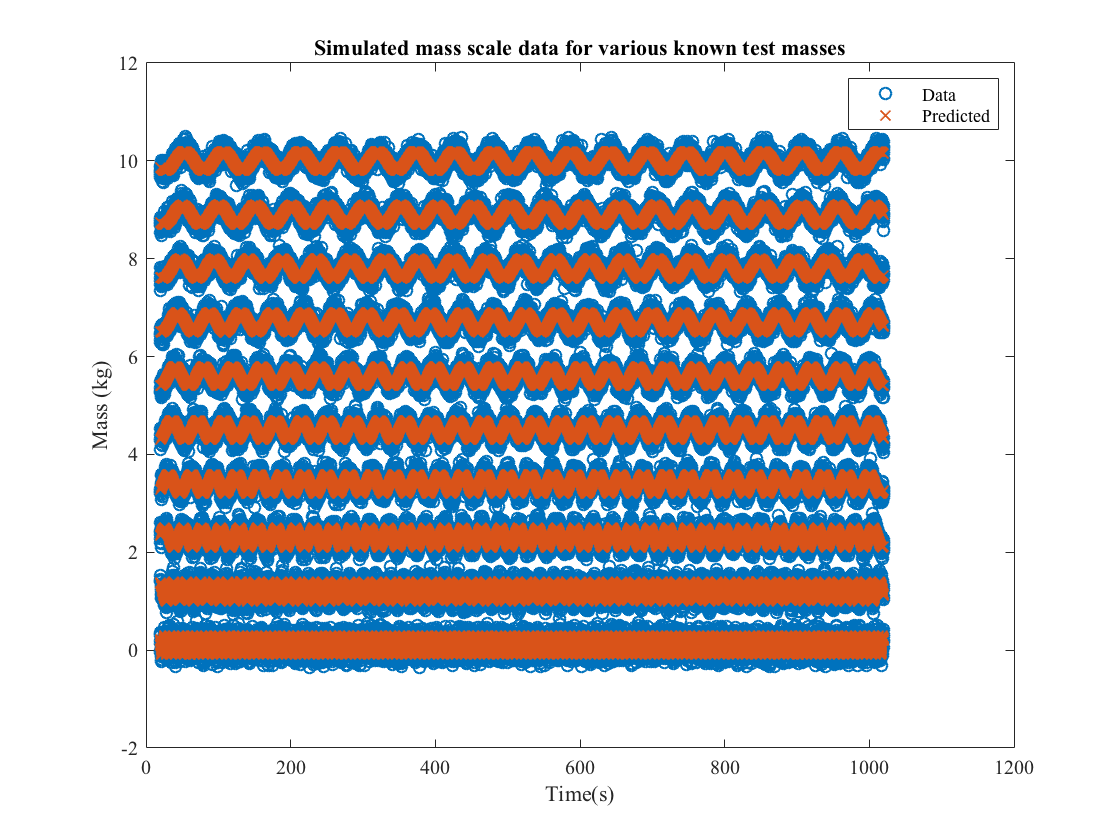

figure
plot(XX(:,2),ygrand,'o',XX(:,2),ypred,'x')
xlabel('Time(s)');ylabel('Mass (kg)');
title('Simulated mass scale data for various known test masses')
legend('Data','Predicted')

Let's zoom in by repeating the plot with axis limits.

xmin=20; xmax=220; ymin=-1; ymax=11;
figure;
plot(XX(:,2),ygrand,'o',XX(:,2),ypred,'x');
axis([xmin xmax ymin ymax]);
xlabel('Time(s)');ylabel('Mass (kg)');
title('Simulated mass scale data for various known test masses')

The zoom view shows individual data points and an excellent fit accounting for mass dependence of frequency and of phase and amplitude of the sinusoidal oscillation.

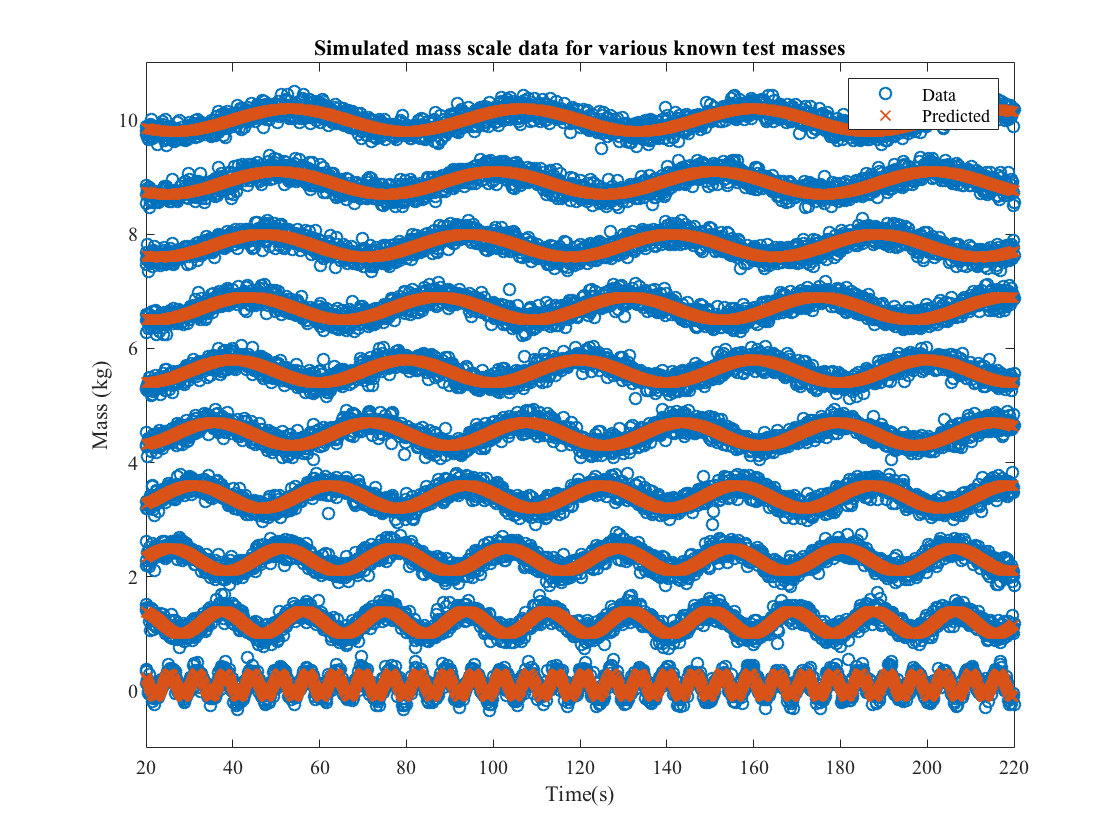

legend('Data','Predicted')

## Plot the residuals from the fit

To histogram residuals, we can invoke a method of mdl

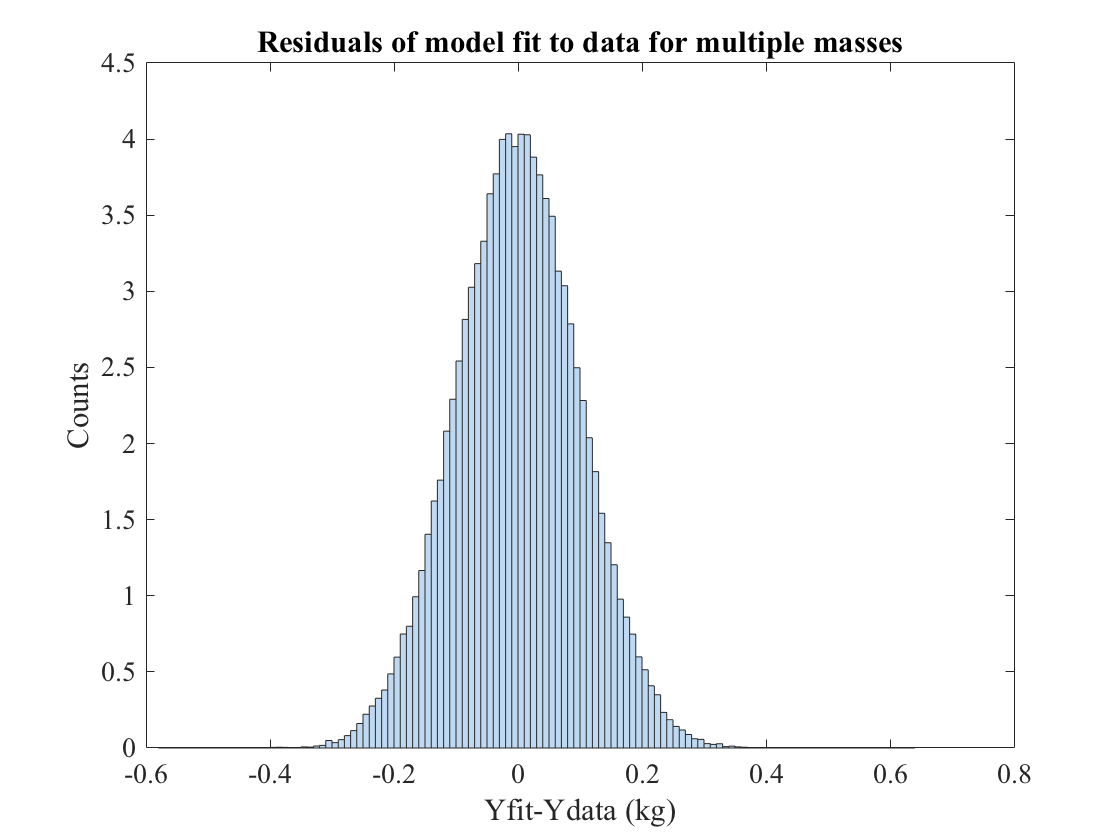

figure;
plotResiduals(mdl)% histogram residuals
title('Residuals of model fit to data for multiple masses')
xlabel('Yfit-Ydata (kg)');ylabel('Counts')

Another  option is the plot the cumulative distribution of residuals.

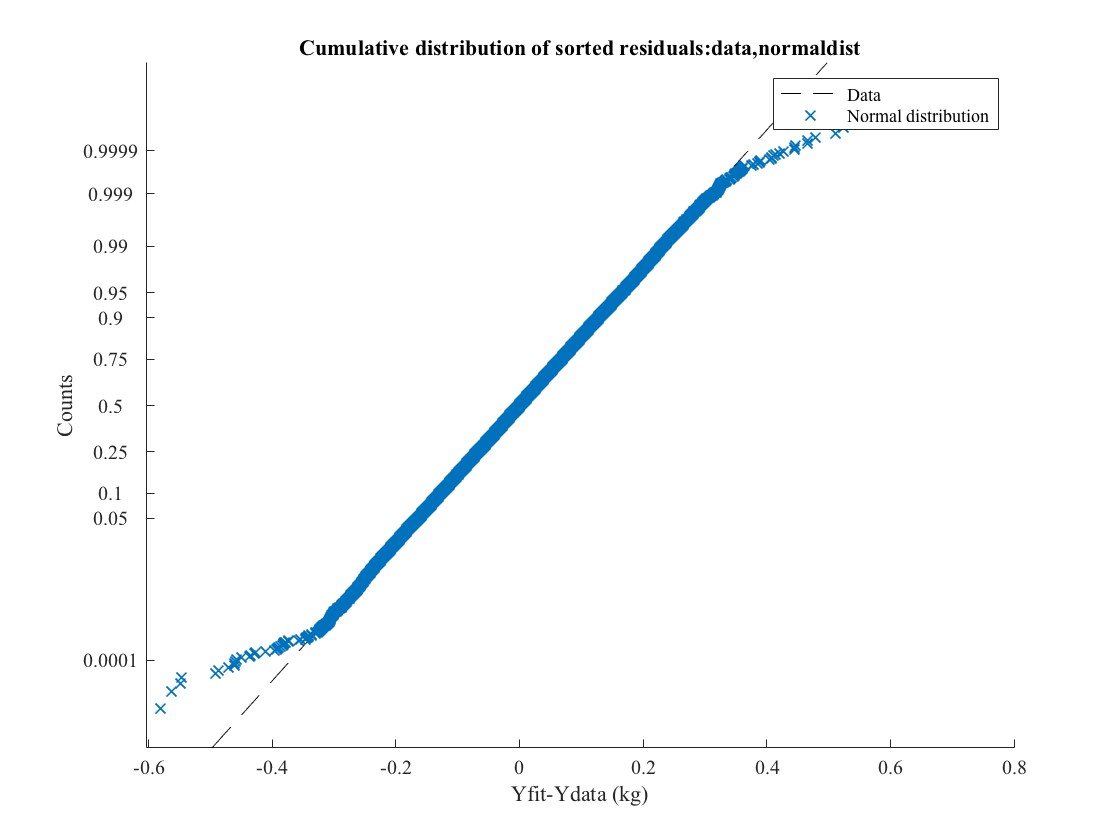

figure;plotResiduals(mdl,'probability');% plot probability
title('Cumulative distribution of sorted residuals:data,normaldist')
xlabel('Yfit-Ydata (kg)');ylabel('Counts')
legend('Data','Normal distribution')

See other methods at https://www.mathworks.com/help/stats/nonlinearmodel-class.html.

We see small tails presumably due to unfiltered rand2 events.

## Evaluation

Having reduced the noise to what appears to be a normal distribution common  to every mass, we can make quantitative predictions about the accuracy.  We expect, with appropriate filtering and use of our time dependent calibration  model, single future measurement values for a known mass will be governed by  a normal distribution with standard deviation sigma= 0.1, with a  possibility of a spurious rand2 contamination. The model function must be used to correct for offset, scale, and the sinusoidal noise,  given a single measurement and time and the mass. In measuring an unknown mass at a fixed time, we would use the inverse of the model function  evaluated at the measured mass to estimate the actual mass. By looking at the plot of measured versus actual mass, we can see the std will depend upon the time and mass but never be much larger than 0.1.

Multiple measurements of an unknown mass should be filtered and corrected and then averaged. A set of n measurements  will have a standard deviation of the mean about equal to sigma/sqrt(n)  until we hit a systematic limit to be determined. (Quantization in the the readout provides a lower bound.)

## Future improvements

We identified a small contamination of rand2 events passing the filter. The shape of the rand2 distribution of filtered events could be studied and extrapolated into the not filtered region to determine the likihood of contamination from such events and the distortion in the tails of the normal distribution. Code to effect the inversion of the model function could be writen, tested, and used to study expected distributions of results for an unknown mass.

## General conclusions and instrument design and use

From what you have seen, it is clear that averaging over time will reduce the impact of both the random and harmonic noise components. Since the instrument is not intended to measure a time variation in mass, an instrument designer might pick a warmup transient window like 20 s to wait before giving results (common in digital bathroom scales), and then use a sliding 10 second averaging time window to produce more accurate values, and present to the user only the time averaged results with, say, 10 second updates. The digital output would be designed to match so random noise fluctuations would be suppressed in the least significant figure.

The reason for ignoring the transient is that it depends on initial conditions. Our simulation assumes the mass starts at rest, but in general the details of the transient motion will depend on just how hard the mass was dropped on the platform. As a practical matter, modelling such behavior is fruitless without an ability to measure the initial velocity of the mass+platform. We will learn that mechanical damping will erase memory of any initial conditions and is optimally chosen such that the damping matches the natural period. The designer might choose the spring and damping to optimize the accuracy for a fixed (dynamic) range of masses. 

To measure a time dependent mass, such as that of a beaker being filled with material, requires an instrument with time averaging (filtering) optimized for the expected time dependence of the signal. Too much averaging will erase oscillatory components in the motion we hope to measure. The design and its characterization are more complex.

The precision and accuracy in this illustration are governed entirely by the steady state vibration and the random noise, both possibly environment dependent. Instrument packages are designed to isolate the measurement system from the environment (vibration isolation via special support structures, electrical isolation through a metallic chassis and filtering of power supply voltages, thermal regulation,...).

## Comparison to existing scales

The specifications for one commerical scale (https://www.socalbiomed.com/ equipment/balances/accuris-analytical-balance-series-0-1mg.html) indicate an accurancy of 0.1mg for up to 100 g or about 1 part in one million after a 30 min warmup and calibration to correct for variations in the surface acceleration of gravity g and other effects. It uses an electromagnet pushing on a permanent magnet as an effective spring maintaining the position of the platform as weight is added. The current in the electromagnet sensed.

In contrast, a typical bathroom scale will give readings off the shelf differing by a few percent or a few pounds for an adult. It may use a lever to amplify a spring compression into a rotation of a needle, or a piezoelectric which converts pressure to voltage with electronic digital display.

Our fanciful noise level and sensitivity is not based in any study, simply chosen for illustration. The noise std of 0.1 corresponds to jitter of about 1/1000 of the displacement for a mass of 10 kg.

A different approach would be to measure the resonant frequency of the mass+spring system using a tuned oscillator to deliberately drive an oscillation. A mass shift will change the resonant response amplitude. A shift in the drive freqeuncy required to compensate can be sensed and the mass calculated. For an application of such principles, see for example https://www.malvernpanalytical.com/en/products/technology/ resonant-mass-measurement .

## The end

disp('End of FakeDataGame. Plots will appear shortly.') ;

End of FakeDataGame. Plots will appear shortly.


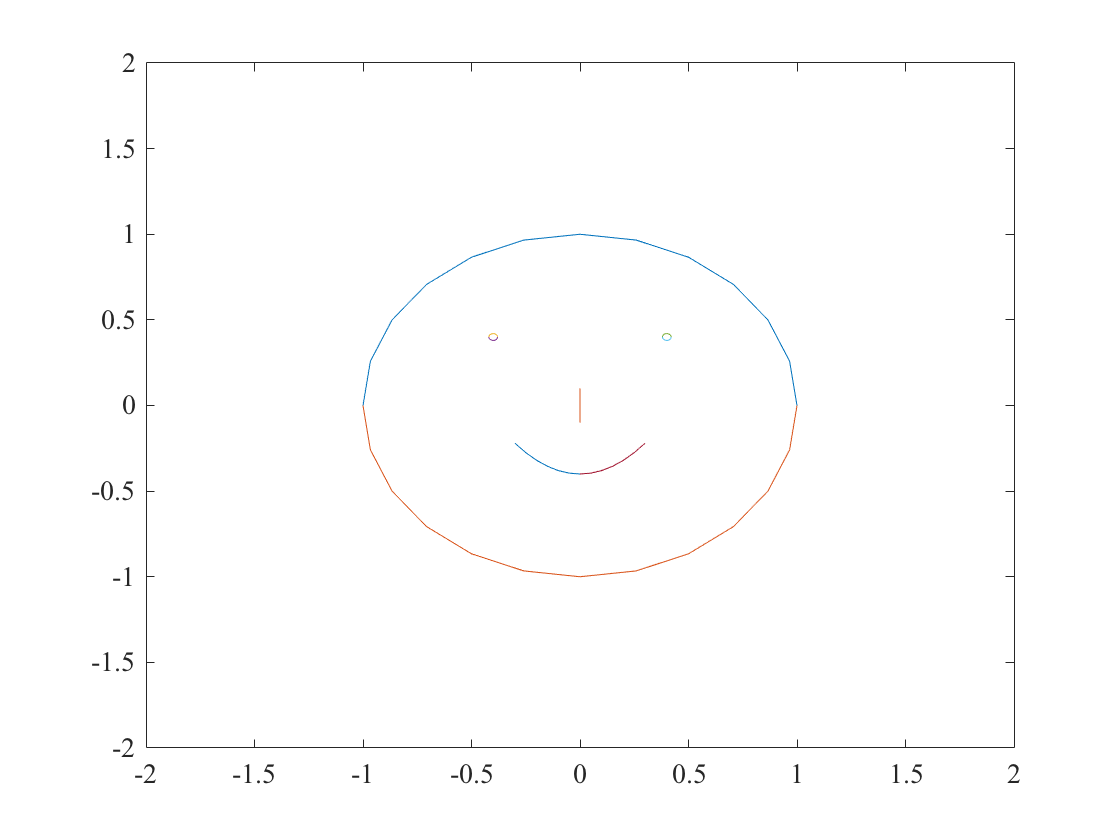

x=smileface;% say goodbye with a smile

function z=filterdata(y,mass, threshold)
% Replace values far from expectation by average on neighbors.
% length(y)
% mass
% threshold
z=y;zavem=mean(z);
for ipeak=1:length(y)
        if ipeak==1
            i2=2;i3=3;
        end
        if ipeak==length(y)
            i2=ipeak-1;i3=ipeak-2;
        end
        if ipeak>1&ipeak<length(y)
            i2=ipeak-1;i3=ipeak+1;
        end
        aveval=(y(i2)+y(i3))/2;diffval=y(i2)-y(i3);
        if abs(y(ipeak)-aveval)>threshold&abs(diffval)<threshold
            z(ipeak)=aveval;
        end
        % if it happens that two flukes sandwich a good point, the good
        % point will be moved so stifle this case
        if abs(z(ipeak)-zavem)>threshold
            z(ipeak)=zavem;
        end
end
end

## FakeScaleDataGameGeneratorFunction.m

Simulate measurements of a spring-based weight scale.

Assume a platform suspended from a linear spring. Mass is placed on the platform and together these undergo a damped oscillation arriving ultimately at a new equilibrium position. We neglect the impact of the damping on the oscillation frequency and assume the mass and platform start from rest and are locked together. One could get the mass from the frequency but we return a noisy measure of the ultimate equilibrium displacement from the no-added mass displacement. There is some sort of readout, ultimately digital. It might be a haptic-like proximity sensor, an optical lever and light sensor, an interferometer (overkill), or acoustic. Or maybe a robot eying a needle and marked scale.

Systematic effects include an equilibrium offset, a damped offset shift, a scale factor shift (the scale is assumed linear otherwise), an initial transient motion assuming the mass and deadweight are released from rest, and a small steady oscillation at the natural frequency for the mass plus deadweight induced by external forcing, the amplitude of which is assumed independent of frequency. More realistically, the amplitudes of driven oscillation would depend on the amplitudes in external forcing at the mass-dependet natural frequency of the spring-mass oscillator. This forcing might be due to a spectrum of environmental vibration of the scale support structure, with those vibrations close to the natural freqeuncy of the spring-mass resonantly driving the oscillation.

Added normally distributed random noise represents other influences affected equally all measurements. These might concern the readout, say jitter in the angle of a light beam.

Normally distributed salt and pepper noise represents glitches which impact randomly selected individual measurements such as electric discharges affecting an electronic digital readout or human error in logging data. A fixed fraction of measurement are affected. The response is clamped within a dynamic range, and digitized with a fixed number of significant figures, introducing a quantization error.

function [y]=FakeDataGameGeneratorFunction(mass,t)
% mass = mass of object to be weighed
% n=length(t) number of measurements of the weight of an object at times t
% times will be in seconds
% y= vector of measurements returned with some close to appropriate 
% scale factor. The scale is determined by the spring constant and that can
% drift due to creep and to work hardening of the spring material.
% Uncomment the following to make reproducible random results.
%rng('default')% Reset seed for random number generator for reproducibility
n=length(t);% number of measurements is the length of the vector t
if n<1 then
    y=zeros(n,1)
    ret='FakeScaleDataGameGeneratorFunction: n < 1 so returning zeros'
    return
end

## Set parameters

Uncomment to set new values while remembering the old

zerooffset= 0.1;%zerooffset=0;
scaleoffset= .1;%scaleoffset=0;
thermalmag=2;%thermalmag=0;
thermaltime = 2;%thermaltime=0;
normalnoisesigma=.1;%normalnoisesigma=0;
mplatform = .1;% mass of platform attached to spring to hold mass
mspring = .03;% effective mass of spring
mdead= mplatform+mspring;
% We are going to pick parameters so the natural frequency f is 1/40 Hz for a
% mass of 5. That will give 2.5 cycles in 100 seconds. The deadweight is
% such that the period is 6 seconds for zero mass.
% We have
% f=(2*pi)^(-1)*(k/(mass+mspring+mplatform))^(1/2)
% so pick a spring constant k accordingly
naturalfrequency=1/40;
kk=(5+mspring+mplatform)*(naturalfrequency*(2*pi))^2;
naturalfrequency=(2*pi)^(-1)*(kk/(mass+mspring+mplatform))^(1/2);
% We will use a simplified model in which the damping time
% is independent of mass. In reality, it might vary inversely with mass.
naturaldampingtime = 4;% Natural damping time
% Displacements with and without mass from the spring natural state
x0=mdead/kk; x1=(mass+mdead/kk);
initialamplitude=x1-x0; %initial amplitude of transient oscillation
% Create sinusoidal transient
transient = initialamplitude*cos(2*pi*t*naturalfrequency)...
    .*(exp(-t/naturaldampingtime));
% Create steady state oscillation with amplitude twice noise std so it will
% be observable in the presence of noise.
steadystate=2*normalnoisesigma*...
    cos(2*pi*t*naturalfrequency);
% Sum offset, plus transient thermal offset drift plus a scale offset
% equilibrium shift, transient response, steady state oscillation,
% and normally distributed random noise.
y= zerooffset*ones(1,n)+thermalmag*exp(-t/thermaltime)+...
(1+scaleoffset)*mass*ones(1,n)...
    +transient+steadystate+ normrnd(0,normalnoisesigma*ones(1,n));
% Add salt and pepper noise.
frac = 0.03;% fraction of events contaminated
spnoise = zeros(size(t));
for ipoint=1:length(t)
    if random('Uniform',0,1)<frac 
     spnoise(ipoint) = normrnd(0,5);% noise add is normal, std=5
    end
end
y = y+spnoise;
minw=-1;maxw=15.5; % dynamic range
y(y<minw)=minw;y(y>maxw)=maxw;% truncate result if outside dynamic range
% digitization
Ndecimals = 4 ;
f = 10.^Ndecimals ;
y = round(f*y)/f;% quantized result is returned.
% Note that we set g=1 above so have implicitly assumed some nominal
% value like 9.81 m-s^2. Use locally implies the absolute scale will be
% off. A calibration can correct for this by measuring with known masses.
% You would not want to rescale to local g after such a calibration.
end
function STATS = fourplot(X)
% FOURPLOT - Four-plot for efficient visual exploratory data analysis
%
%   FOURPLOT(X) creates for the values in X a "four-plot" that allows for a
%   powerful and efficient visual inspection of the four underlying
%   assumptions of univariate statistical analyses. Descriptive statistics
%   are printed out in the command window.
%
%   X is a vector of observational values. It should be numerical and
%   cannot contain NaNs or Infs. 
% 
%   In four subplots, the run sequence plot (X[k] vs k), a lag plot (X[k]
%   vs X[k-1]), a histogram, and a normal probablity plot are shown. Within
%   these axes, the mean value of X is drawn as a straight line. In
%   addition, a 5th panel shows a box-and-whisker plot of X.
%
%   If the four underlying assumptions holds, the four plots will have a
%   characteristic appearance.
%   1. If the fixed location assumption holds, then the run sequence plot
%      will be flat and non-drifting. 
%   2. If the fixed variation assumption holds, then the vertical spread in
%      the run sequence plot will be the approximately the same over the
%      entire horizontal axis.
%   3. If the randomness assumption holds, then the lag plot will be
%      structureless and random. 
%   4. If the fixed distribution assumption holds, in particular if the
%      fixed normal distribution holds, then the histogram will be
%      bell-shaped, and the normal probability plot will be linear.
%
%   The box-and-whisker plot will show the median (red line), mean and SD (in
%   blue), the 25th and 75th percentile (the box), and outliers (plus
%   symbols), if any. The whiskers are the lowest value still within 1.5
%   times the inter-quartile range (IQR) of the lower quartile, and the
%   highest value still within 1.5 IQR of the upper quartile. Raw data are
%   plotted in gray.
%
%   STATS = FOURPLOT(X) returns some statistical values in the
%   structure STATS. Descriptive statistics are not printed.
%
%   Examples:
%     % case 1: the four assumptions hold
%       X = 20 + randn(100,1) * 10 ; 
%       fourplot(X) % nice, we can use classical statistics!
%
%     % case 2: data is oscillating, which is not immediately clear
%       unknown = cumsum(rand(1000,1)) ;  
%       unknown = unknown(randperm(numel(unknown))) ;
%       X = sin(unknown) ; % X looks random (see, e.g., run sequence) ..
%       fourplot(X)        % .. but it is not!
%
%   The usefulness of a four-plot extends beyond inspection of univariate
%   and time series data. For instance, it can be used to inspect the
%   residuals of model fit to determine whether the underlying error term
%   of the model fullfills the assumptions, no  matter how complicated the
%   model may be. 
%
%   Example:
%       x = 2*rand(100,1) ; y = exp(x) ; % the complex data
%       par = polyfit(x,y,1) ;           % a (too) simple model
%       res = y - polyval(par,x) ;       % residuals
%       fourplot(res)                    % -> our model is poor!
%
%   More information can be found on the internet, e.g.,
%   http://www.itl.nist.gov/div898/handbook/eda/section2/eda23.htm
%
%   See also NORMPLOT (Statistics Toolbox)
%            MEAN, MEDIAN

% tested in Matlab 2010b, but should work in most ML releases
% version 3.0 (march 2015)
% (c) Jos van der Geest
% email: jos@jasen.nl

% History
% 1.0 (july 2013) created
% 2.0 (july 2013) box-and-whisker plot added
% 3.0 (march 2015) print output of descriptive statistics 

% a few sanity checks on the input
narginchk(1,1) ;
N = numel(X) ;
if N<1 || ~isnumeric(X), 
    error('Data should be a numerical vector with some values.') ;
end
X = reshape(X,1,N) ; % make a row vector
if any(isnan(X) | ~isfinite(X)),
    error('Data cannot contain NaNs/Infs.') ;
end

minmaxX = [min(X) max(X)] ;
if minmaxX(1)==minmaxX(2),
    error('No variation in data. Nothing to do, really ...') ;
else
    % data limits are use to scale the plots properly
    datalimits = minmaxX + (0.02 * [-1 +1] .* (minmaxX(2)-minmaxX(1))) ;
end

ix = 1:N ;
MeanX = mean(X) ; % mean is used as a reference line in the plots
SDX = std(X) ;    % standard deviation

% create a new figure, holding the four subplots
figure ('name','4-Plot') ;

% ---------------------------------------------
% plot 1 - RUN SEQUENCE
ah(1) = subplot(2,3,1) ;

hold on ;
plot([0 N+1],[MeanX MeanX],'b-') ;  % reference line
plot(ix, X, 'b.-') ; 

hold off ;
xlabel('k') ;
ylabel('X(k)') ;
title('RUN SEQUENCE') ;

% ---------------------------------------------
% plot 2 - LAG
ah(2) = subplot(2,3,2) ;

hold on ;
plot([datalimits NaN MeanX MeanX], ...
    [MeanX MeanX NaN datalimits],'b-') ; % reference line
plot(X([2:end 1]), X,'b+') ;

hold off ;
xlabel('X(k-1)') ;
ylabel('X(k)') ;
title('LAG') ;

% ---------------------------------------------
% plot 3 - HISTOGRAM
ah(3) = subplot(2,3,4) ; 

[Nh,Xh] = hist(X(:),10) ; % count into 10 bins
Nh = Nh ./ N ; % proportions

hold on ;
bar(Xh,Nh) ;
plot([MeanX MeanX],get(ah(3),'ylim'),'b-') ; % reference line

hold off ; 
xlabel('Value') ;
ylabel('Proportion') ;
title('HISTOGRAM') ;

% ---------------------------------------------
% plot 4 - NORMAL PROBABLITY
ah(4) = subplot(2,3,5) ; 
X = sort(X) ; % sort the data
P = -sqrt(2)*erfcinv(2*(ix-0.5)/N) ; % the normal probabilities for each index

hold on ;
plot(X,P,'b+') ; 
par = polyfit(X,P,1); % fit a straight line to visualize deviations
plot(datalimits,polyval(par,datalimits),'r-') ; % fit
plot([datalimits NaN MeanX MeanX],[0 0 NaN get(ah(4),'ylim')],'b-') ; % reference line

hold off ;
xlabel('sorted X') ;
ylabel('Probability') ;
title('NORMAL PROBABLITY') ;

% ---------------------------------------------
% plot 5 - BOXPLOT
ah(5) = subplot(2,3,[3 6]) ; hold on ;

% calculate the various parts of the Box plot
XQ = zeros(5,1) ; % pre-allocation
ixq = round([.25 .5 .75]*N) ; %25, 50, and 75th percentile
ixq(ixq<1) = 1 ; 
XQ(2:4) = X(ixq) ; % 1st, 2nd (median), and 3rd quartile (Q25, Q50, & Q75)
IQR = XQ(4)-XQ(2) ;  % inter-quartile range IQR
IsOutlierBelow = X < XQ(2) - 1.5 * IQR ; 
XQ(1) = min(X(~IsOutlierBelow)) ; % lowest value within 1.5 times the IQR below Q25
IsOutlierAbove = X > XQ(4) + 1.5 * IQR ;
XQ(5) = max(X(~IsOutlierAbove)) ; % highest value within 1.5 times the IQR above Q75
IsOutlier = IsOutlierBelow | IsOutlierAbove ;
Xout = X(IsOutlier) ;  % outliers




% plotting individual values with a little jitter
xposjitter = ((0:N-1)-(N/2))./(2*N) ; 
xposjitter = xposjitter(randperm(N)) ;
xph = plot(xposjitter,X,'ko') ;
set(xph,'markeredgecolor',[.7 .7 .7],'markerfacecolor',[.7 .7 .7],'markersize',4) ; 

% create the box-and-whisker-plot
tempy = MeanX + [1 1 1 -1 -1 -1] * SDX ;
tempx = 0.2 + [-1 1 0 0 -1 1] * 0.05 ;

plot(tempx, tempy,'b-') ; % standard deviation error bars
plot(0.2,MeanX,'bs', 'markerfacecolor', 'b') ; % mean value
plot([-1 1],XQ([3 3]),'r-') ; % median
plot([-1 -1 1 1 -1],XQ([2 4 4 2 2]),'k-') ; % box
plot([0 0 -1 1]/2,XQ([4 5 5 5]),'k-') ; % whiskers at 1.5
plot([0 0 -1 1]/2,XQ([2 1 1 1]),'k-') ;
plot(xposjitter(IsOutlier), Xout,'k+') ;
hold off ;

title('BOXPLOT') ;
ylabel('Values') ;
set(ah(5),'xtick',[],'xlim',[-1.5 1.5]) ;

% ---------------------------------------------
% make the limits congruent for easier inpsection
set(ah([2 3 4]),'xlim', datalimits) ;
set(ah([1 2 5]),  'ylim', datalimits) ;
set(ah(1),'xlim',[0 N+1]) ;
set(ah,'box','on') ;

if nargout,
    % return some statistics
    STATS.N    = N ;
    STATS.mean = MeanX ;
    STATS.SD   = SDX ;
    STATS.Q25  = XQ(2) ;
    STATS.Q50  = XQ(3) ;
    STATS.Q75  = XQ(4) ;
    STATS.IQR  = IQR ;
    STATS.SortedValues = X ;
    STATS.IsOutlier = IsOutlier ;
else
    % print out descriptives
    disp('FOUR PLOT') ;
    fprintf('  N     : %d\n', N) ;
    fprintf('  Mean  : %.2f\n', MeanX) ;
    fprintf('  SD    : %.2f\n', SDX) ;
    fprintf('  Var   : %.2f\n', var(X)) ;
    fprintf('  Minimum  : %.2f\n', minmaxX(1)) ;
    fprintf('  Maximum  : %.2f\n', minmaxX(2)) ;
    fprintf('  Median   : %.2f\n', XQ(3)) ;
    fprintf('  Q25      : %.2f\n', XQ(2)) ;
    fprintf('  Q75      : %.2f\n', XQ(4)) ;
    fprintf('  IQR      : %.2f\n', IQR) ;
    fprintf('  # outliers below : %d\n', sum(IsOutlierBelow)) ;
    fprintf('  # outliers above : %d\n', sum(IsOutlierAbove)) ;
end
    
end
function varargout = ds2nfu(varargin)
% DS2NFU  Convert data space units into normalized figure units. 
%
% [Xf, Yf] = DS2NFU(X, Y) converts X,Y coordinates from
% data space to normalized figure units, using the current axes.  This is
% useful as input for ANNOTATION.  
%
% POSf = DS2NFU(POS) converts 4-element position vector, POS from
% data space to normalized figure units, using the current axes.  The
% position vector has the form [Xo Yo Width Height], as defined here:
%
%      web(['jar:file:D:/Applications/MATLAB/R2006a/help/techdoc/' ...
%           'help.jar!/creating_plots/axes_pr4.html'], '-helpbrowser')
%
% [Xf, Yf] = DS2NFU(HAX, X, Y) converts X,Y coordinates from
% data space to normalized figure units, on specified axes HAX.  
%
% POSf = DS2NFU(HAX, POS) converts 4-element position vector, POS from
% data space to normalized figure units, using the current axes. 
%
% Ex.
%       % Create some data
% 		t = 0:.1:4*pi;
% 		s = sin(t);
%
%       % Add an annotation requiring (x,y) coordinate vectors
% 		plot(t,s);ylim([-1.2 1.2])
% 		xa = [1.6 2]*pi;
% 		ya = [0 0];
% 		[xaf,yaf] = ds2nfu(xa,ya);
% 		annotation('arrow',xaf,yaf)
%
%       % Add an annotation requiring a position vector
% 		pose = [4*pi/2 .9 pi .2];
% 		posef = ds2nfu(pose);
% 		annotation('ellipse',posef)
%
%       % Add annotations on a figure with multiple axes
% 		figure;
% 		hAx1 = subplot(211);
% 		plot(t,s);ylim([-1.2 1.2])
% 		hAx2 = subplot(212);
% 		plot(t,-s);ylim([-1.2 1.2])
% 		[xaf,yaf] = ds2nfu(hAx1,xa,ya);
% 		annotation('arrow',xaf,yaf)
% 		pose = [4*pi/2 -1.1 pi .2];
% 		posef = ds2nfu(hAx2,pose);
% 		annotation('ellipse',posef)

% Michelle Hirsch
% mhirsch@mathworks.com
% Copyright 2006-2014 The MathWorks, Inc

## Process inputs

error(nargchk(1, 3, nargin))

% Determine if axes handle is specified
if length(varargin{1})== 1 && ishandle(varargin{1}) && strcmp(get(varargin{1},'type'),'axes')	
	hAx = varargin{1};
	varargin = varargin(2:end);
else
	hAx = gca;
end;

errmsg = ['Invalid input.  Coordinates must be specified as 1 four-element \n' ...
	'position vector or 2 equal length (x,y) vectors.'];

% Proceed with remaining inputs
if length(varargin)==1	% Must be 4 elt POS vector
	pos = varargin{1};
	if length(pos) ~=4, 
		error(errmsg);
	end;
else
	[x,y] = deal(varargin{:});
	if length(x) ~= length(y)
		error(errmsg)
	end
end

## Get limits

axun = get(hAx,'Units');
set(hAx,'Units','normalized');
axpos = get(hAx,'Position');
axlim = axis(hAx);
axwidth = diff(axlim(1:2));
axheight = diff(axlim(3:4));

## Transform data

if exist('x','var')
	varargout{1} = (x-axlim(1))*axpos(3)/axwidth + axpos(1);
	varargout{2} = (y-axlim(3))*axpos(4)/axheight + axpos(2);
else
	pos(1) = (pos(1)-axlim(1))/axwidth*axpos(3) + axpos(1);
	pos(2) = (pos(2)-axlim(3))/axheight*axpos(4) + axpos(2);
	pos(3) = pos(3)*axpos(3)/axwidth;
	pos(4) = pos(4)*axpos(4)/axheight;
	varargout{1} = pos;
end

## Restore axes units

set(hAx,'Units',axun)

end
function y=smileface
% https://www.mathworks.com/matlabcentral/fileexchange/31913-happy-face
figure
x1=[1 cos(pi/12) cos(pi/6) cos(pi/4) cos(pi/3) cos(5*pi/12) cos(pi/2) -cos(5*pi/12) -cos(pi/3) -cos(pi/4) -cos(pi/6) -cos(pi/12) -1];
l=length(x1);
for i=1:l
    y1(i)=sqrt(1-(x1(i)^2));
end
plot(x1,y1)

yr1=-y1;
hold on
plot(x1,yr1)
% xx=0:0.01:1;
% yy = spline(x,y,xx);
% plot(x,y,'o',xx,yy);
% % plot(x,y,xx)


x2=0.02*x1-0.4;
y2=0.02*y1+0.4;
yr2=-y2+0.8;

plot(x2,y2)
plot(x2,yr2)

x3=0.02*x1+0.4;
y3=0.02*y1+0.4;
yr3=-y3+0.8;

plot(x3,y3)
plot(x3,yr3)

x4=[0 0.05 0.1 0.15 0.2 0.25 0.3];
l1=length(x4);
for i=1:l1
    y4(i)=2*(x4(i)^2)-0.4;
end
plot(x4,y4)

x5=-x4;
plot(x5,y4)

x6=[0 0 0];
y6=[-0.1 0 0.1];
plot(x6,y6)
axis([-2 2 -2 2]);
y=1;
end